# Notas de clase: Sistemas Lineales

## Clase 1: Presentación del curso

## Clase 2: Repaso de ecuaciones diferenciales ordinarias

clear,clc

### Definiciones

- **Ecuación diferencial: **Ecuación que contiene derivadas

- **Ecuación diferenciales ordinarias: **Aplicación de las ecuaciones diferenciales a sistemas donde los parámetros son concentrados (todas las propiedades del sistema se resumen a un punto, es decir, se minimizan las variables independientes necesarias). **Ejemplo: **$f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)=0,\;\;\;\;\overset{\ldotp }{y} =\frac{\mathrm{d}}{\mathrm{d}t}y$

- **Ecuaciones diferenciales parciales: **Aplicación a sistemas con parámetros distribuidos (las propiedades del sistema requieren más de una variable para expresarse)

- **Ecuaciones lineales: **Se dice que una ecuación diferencial de n-ésimo orden es lineal si $f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)$ es lineal en $y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y}$. Dicho de otra forma, la ecuación diferencial de n-ésimo orden es lineal si tiene la forma $a_n \left(t\right)\overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 \left(t\right)y=u\left(t\right)$.

- **Ecuaciones lineales con coeficientes constantes: **Se les conoce como **LTI **(Linear-Time-Invariant). Los coeficientes que acompañan a la variable dependiente no cambian con el tiempo, por tanto, son de la forma $a_n \overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 y=u\left(t\right)\ldotp$ Existen métodos analíticos para resolver estas ecuaciones. El término $u\left(t\right)$tiene significado como la entrada del sistema.

- **Problema de valor inicial: **Es un problema de la forma $\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right) & \\
y\left(0\right)=y_{01} ,\ldotp \ldotp \ldotp ,\overset{\left(n-1\right)}{y\left(0\right)} =y_{0n}  & 
\end{array}\right.$

- **Solución general de un problema de valor inicial: **Se calcula la solución general como la suma de la solución de la ecuación complementaria homogénea ($y_c$) y una solución particular de la ecuación no homogénea ($y_p$). De forma tal, la solución general viene dada por $y\left(t\right)=y_c \left(t\right)+y_p \left(t\right)$.

- **Solución **$y_c \left(t\right)$**de la ecuación homogénea **($u\left(t\right)=0$)**: **Se obtiene el polinomio característico y se resuelve para obtener los valores característicos. Debe lidiarse con los casos de valores característicos reales diferentes, complejos diferentes y raíces múltiples. El polinomio característico de $\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right)$ es de la forma $\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_{n-1} \lambda +a_n =0$.

- **Solución **$y_p \left(t\right)$**de la ecuación no homogénea: **Se puede resolver aplicando el método de coeficientes indeterminados (método especial pero simple) o el método de variación de parámetros (método general pero complejo). Para ambos métodos consultar el libro de [Dennis G. Zill & Warren S. Wright](https://www.booksfree.org/differential-equation-by-dennis-g-zill/).

### Ejemplos

#### 1) La ecuación diferencial como definición de un campo vectorial

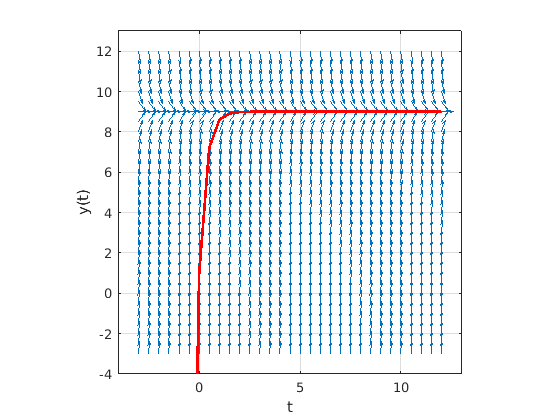

t=-3:0.5:12; y=-3:0.5:12; % define grid of values in t and y directions
[T,Y]=meshgrid(t,y); % creates 2d matrices
dT=ones(size(T)); % dt=1 for all points
dY=27-3*Y; % dy=(t^2-y)*dt: this is the ODE
N=sqrt(dT.^2+dY.^2); % magnitude of arrows
dT=dT./N; % normalize arrows to get all same length
dY=dY./N;
figure(1)
clf
quiver(T,Y,dT,dY) % draw arrows (t,y) --> (t+dt,y+dy)
axis equal
axis([-4 13 -4 13]) % repeat adjustments...
grid on
hold on
C1=8;
y=9-C1*exp(-3*t);
plot(t,y,'r','LineWidth',2);
hold off
xlabel('t')
ylabel('y(t)')

#### 2) Solución de ecuación homogénea

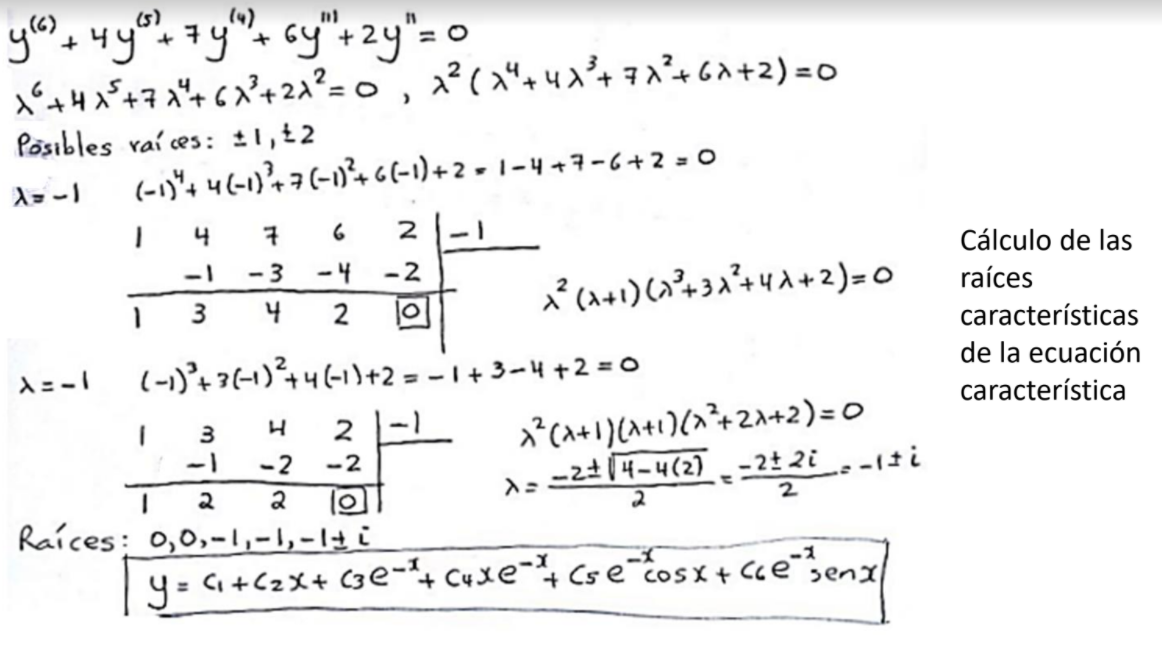

**Comprobación de la solución en MatLab**

syms y(x)
ode=diff(y,6)+4*diff(y,5)+7*diff(y,4)+6*diff(y,3)+2*diff(y,2)==0

$$ode(x) = \frac{\partial^{6}}{\partial x^{6}}y\left(x\right)+4\,\frac{\partial^{5}}{\partial x^{5}}y\left(x\right)+7\,\frac{\partial^{4}}{\partial x^{4}}y\left(x\right)+6\,\frac{\partial^{3}}{\partial x^{3}}y\left(x\right)+2\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)=0$$

ySol(x) = dsolve(ode)

$$ySol(x) = C_{2}-\frac{3\,C_{1}}{2}+\frac{C_{1}\,x}{2}+C_{3}\,{\mathrm{e}}^{-x}+C_{4}\,x\,{\mathrm{e}}^{-x}+C_{5}\,{\mathrm{e}}^{-x}\,\cos\left(x\right)-C_{6}\,{\mathrm{e}}^{-x}\,\sin\left(x\right)$$

#### 3) Solución de ecuación no homogénea

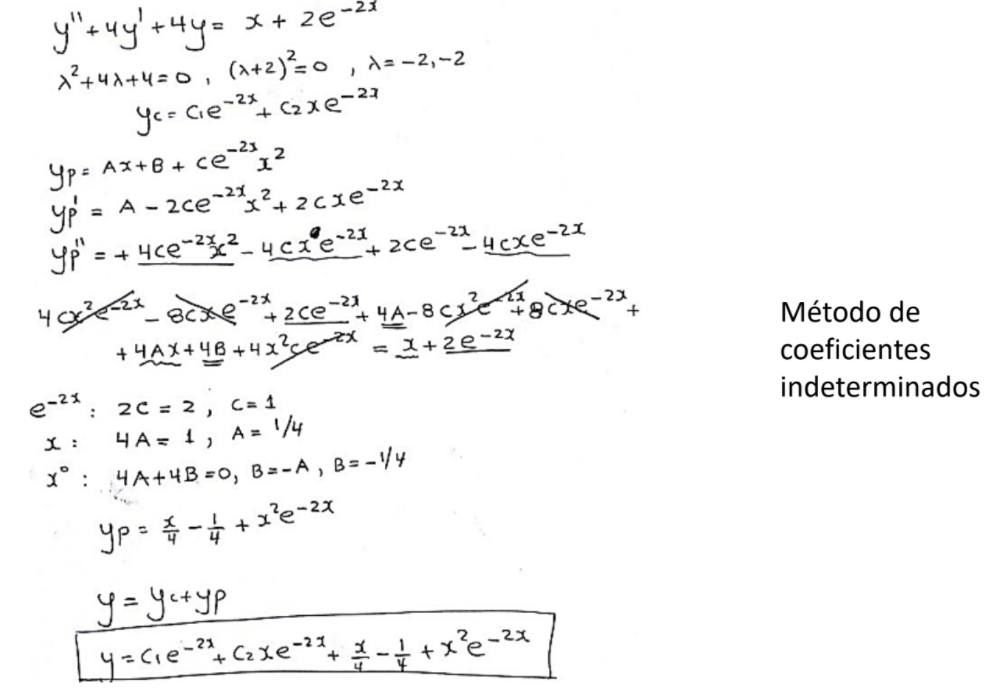

**Comprobación de la solución en MatLab**

ode2=diff(y,2)+4*diff(y)+4*y==x+2*exp(-2*x)

$$ode2(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+4\,\frac{\partial }{\partial x}y\left(x\right)+4\,y\left(x\right)=x+2\,{\mathrm{e}}^{-2\,x}$$

ySol2(x) = simplify(dsolve(ode2))

$$ySol2(x) = \frac{x}{4}+x^{2}\,{\mathrm{e}}^{-2\,x}+C_{1}\,{\mathrm{e}}^{-2\,x}+C_{2}\,x\,{\mathrm{e}}^{-2\,x}-\frac{1}{4}$$

**Solución con condiciones iniciales**

y_0=2; y_1=3;
conds = [y(0)==y_0; y(1)==y_1];
ySol3(x)=dsolve(ode2,conds)

$$ySol3(x) = \frac{{\mathrm{e}}^{-2\,x}\,\left(x\,{\mathrm{e}}^{2\,x}-{\mathrm{e}}^{2\,x}-13\,x+12\,x\,{\mathrm{e}}^{2}+4\,x^{2}+9\right)}{4}$$

## Clase 3: Ecuaciones en diferencias

clear;clc

### Definiciones

- **Ecuación en diferencias: **Es una ecuación que contiene diferencias ($\Delta$).

- **Diferencias hacia adelante: **$\Delta y\left(\textrm{kT}\right)=\frac{y\left(\left(k+1\right)T\right)-y\left(\textrm{kT}\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(\textrm{kT}\right)=\frac{\Delta y\left(\left(k+1\right)T\right)-\Delta y\left(\textrm{kT}\right)}{T}=\frac{y\left(\left(k+2\right)T\right)-2y\left(\left(k+1\right)T\right)+y\left(\textrm{kT}\right)}{T^2 }$

- **Diferencias hacia atrás: **$\Delta y\left(\textrm{kT}\right)=\frac{y\left(\textrm{kT}\right)-y\left(\left(k-1\right)T\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(\textrm{kT}\right)=\frac{\Delta y\left(\textrm{kT}\right)-\Delta y\left(\left(k-1\right)T\right)}{T}=\frac{y\left(\textrm{kT}\right)-2y\left(\left(k-1\right)T\right)+y\left(\left(k-2\right)T\right)}{T^2 }$

- **Forma canónica de una ecuación en diferencias hacia adelante: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(n-1\right)=y_{0n}  & 
\end{array}\right.$

- **Forma canónica de una ecuación en diferencias hacia atrás: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k\right)+a_1 y\left(k-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k-n\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(-1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(-n\right)=y_{0n}  & 
\end{array}\right.$

### Ecuación en diferencias a partir de una ecuación diferencial:

Supongamos que deseamos discretizar la ecuación $\frac{d}{\mathrm{d}t}y+\textrm{ay}=u\left(t\right),y\left(0\right)=y_0$, para ello debemos notar que $\frac{d}{\mathrm{d}t}y\simeq \frac{y\left(k\right)-y\left(k-1\right)}{T}$ (diferencias hacia atrás) y por ende podemos reescribir la ecuación como $\frac{y\left(k\right)-y\left(k-1\right)}{T}+\textrm{ay}\left(k-1\right)=u\left(\left(\left(k-1\right)T\right.\right)\Longrightarrow y\left(k\right)+\left(\textrm{aT}-1\right)y\left(k-1\right)=\textrm{Tu}\left(\left(k-1\right)T\right)$, de forma tal, el problema original se convierte en $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-\textrm{aT}\right)y\left(k-1\right)+\textrm{Tu}\left(\left(k-1\right)T\right) & \\
y\left(0\right)=y_0  & 
\end{array}\right.$

#### Ejemplo: Ecuación en diferencias hacia atrás de orden 2

Resolver la ecuación en diferencias dada por $\left\lbrace \begin{array}{ll}
y\left(k\right)+0\ldotp 9y\left(k-1\right)+0\ldotp 14y\left(k-2\right)=0\ldotp 3u\left(k-1\right)-0\ldotp 6u\left(k-2\right), & u\left(k\right)=\delta \left(k-1\right)=\left\lbrace \begin{array}{ll}
1 & k=1\\
0 & k\not= 1
\end{array}\right.\\
y\left(0\right)=y\left(1\right)=0 & 
\end{array}\right.$

Solucionamos aprovechando la relación de recurrencia:


$$\begin{array}{l}
y\left(k\right)=-0\ldotp 9y\left(k-1\right)-0\ldotp 14y\left(k-2\right)+0\ldotp 3\delta \left(k-2\right)-0\ldotp 6\delta \left(k-3\right)\\
y\left(2\right)=-0\ldotp 9y\left(1\right)-0\ldotp 14y\left(0\right)+0\ldotp 3\delta \left(0\right)-0\ldotp 6\delta \left(-1\right)=0\ldotp 3\\
y\left(3\right)=-0\ldotp 9y\left(2\right)-0\ldotp 14y\left(1\right)+0\ldotp 3\delta \left(1\right)-0\ldotp 6\delta \left(0\right)=-0\ldotp 9\left(0\ldotp 3\right)-0\ldotp 6=-0\ldotp 87\\
\vdots 
\end{array}$$


**Nota: **Es posible utilizar más de un método de discretización para aproximar las derivada, por ejemplo el método de Runge-Kutta4 o el método de Heun.

#### Comparación entre solución discretizada y la solución de la ecuación diferencial discretizada

Supongamos que tenemos la ecuación $\frac{d}{\mathrm{d}t}y+\textrm{ay}=e^{-t} ,\;y\left(0\right)=2$, al discretizar con $T$ llegamos a la expresión $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-\textrm{aT}\right)y\left(k-1\right)+{\textrm{Te}}^{-T\left(k-1\right)}  & \\
y\left(0\right)=y_o  & 
\end{array}\right.$. Para resolver esta ecuación en el intervalo $\left\lbrack 0\;,10\right\rbrack$ podemos implementar el siguiente código

T=0.21;
a=1;
y_0=-4;
time=0:T:10;

%%%% Solución continua
syms y(t)
ode = diff(y)+a*y-exp(-t)==0

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)-{\mathrm{e}}^{-t}+y\left(t\right)=0$$

cond = y(0)==y_0;
ySol(t)=dsolve(ode,cond)

$$ySol(t) = {\mathrm{e}}^{-t}\,\left(t-4\right)$$

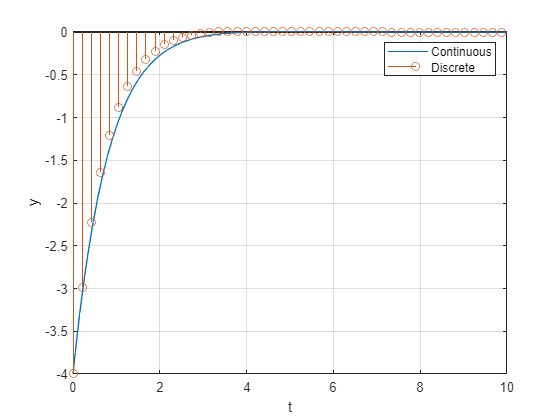


%%%% Solución discreta
yDis=t;
yCont=yDis;
yDis(1)=y_0;
for k=[1:length(time)-1]+1
    yDis(k)=(1-a*T)*yDis(k-1)+T*exp(-T*(k-1));
end

%%%%%%% Comparación entre soluciones
figure(1)
clf
fplot(ySol,[0 10])
grid on
hold on
stem(time,vpa(yDis))
xlabel('t')
ylabel('y')
legend({'Continuous','Discrete'})

#### T implícito vs T explícito

Una vez se ha obtenido la ecuación en diferencias a partir de la ecuación diferencial es posible omitir el instante en el tiempo y concentrarse solo en el número de muestreo actual (T implícito). Para graficar adecuadamente es necesario recordar que $t=\textrm{kT}$.

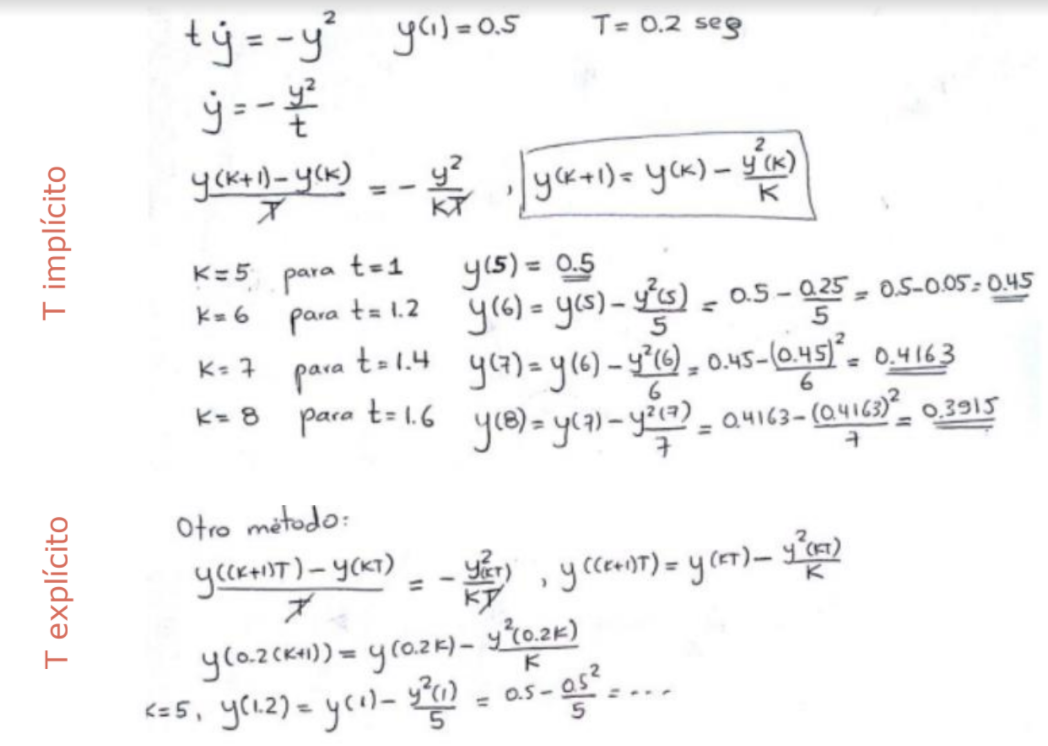

### Solución analítica de una ecuación en diferencias

De la misma forma que se pueden solucionar las ecuaciones diferenciales LTI, es posible plantear un problema de autovalores para las ecuaciones en diferencias. Sea tal solución $\phi =e^{\gamma k}$, reemplazamos en la ecuación en diferencias  $y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=0$ para obtener $e^{\gamma \left(k+n\right)} +a_1 e^{\gamma \left(k+n-1\right)} +\ldotp \ldotp \ldotp +a_n e^{\gamma k} =0\Longrightarrow e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=0$, ahora, introduciendo el cambio de variable $\lambda =e^{\gamma }$ tenemos que $e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=\lambda^k \left(\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n \right)=0\Longrightarrow \lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n =0$, lo cual se cumplirá para $\lambda \in \left\lbrace \lambda_1 ,\ldotp \ldotp \ldotp ,\lambda_n \right\rbrace$. Resta notar entonces que $\phi =e^{\gamma k} =\lambda^k$ para encontrar las soluciones de la ecuación.

#### Primer ejemplo de solución analítica

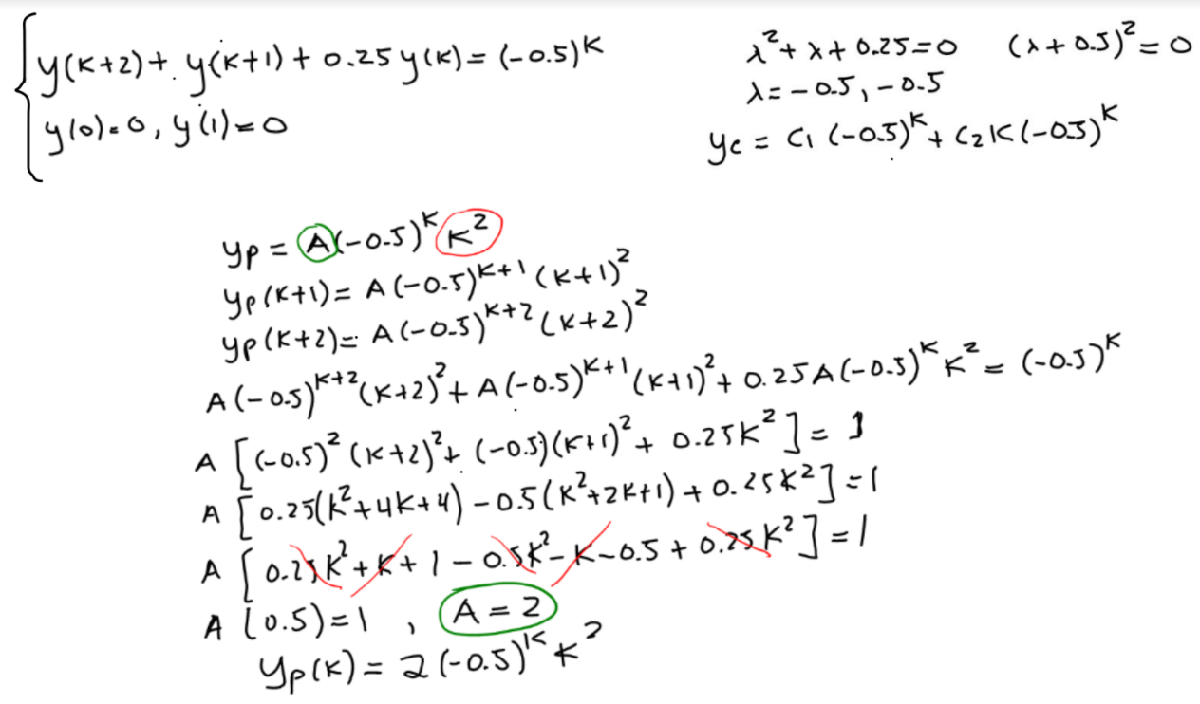

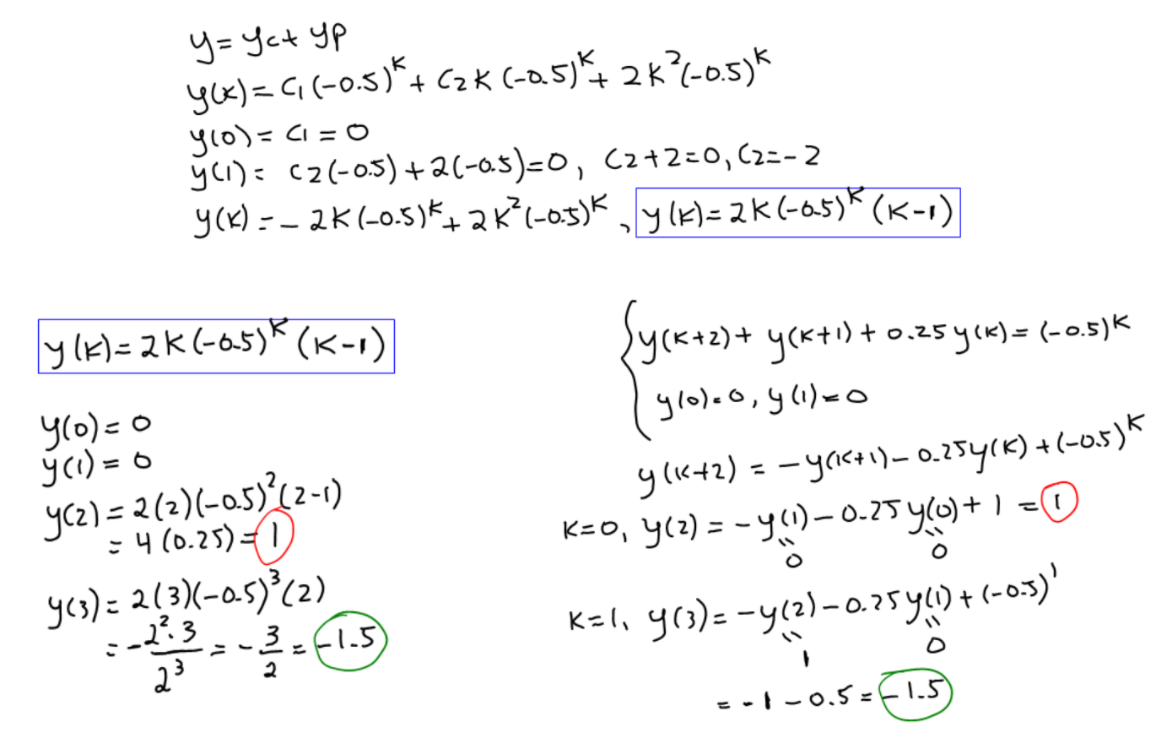

#### Segundo ejemplo de solución analítica: lambda imaginario

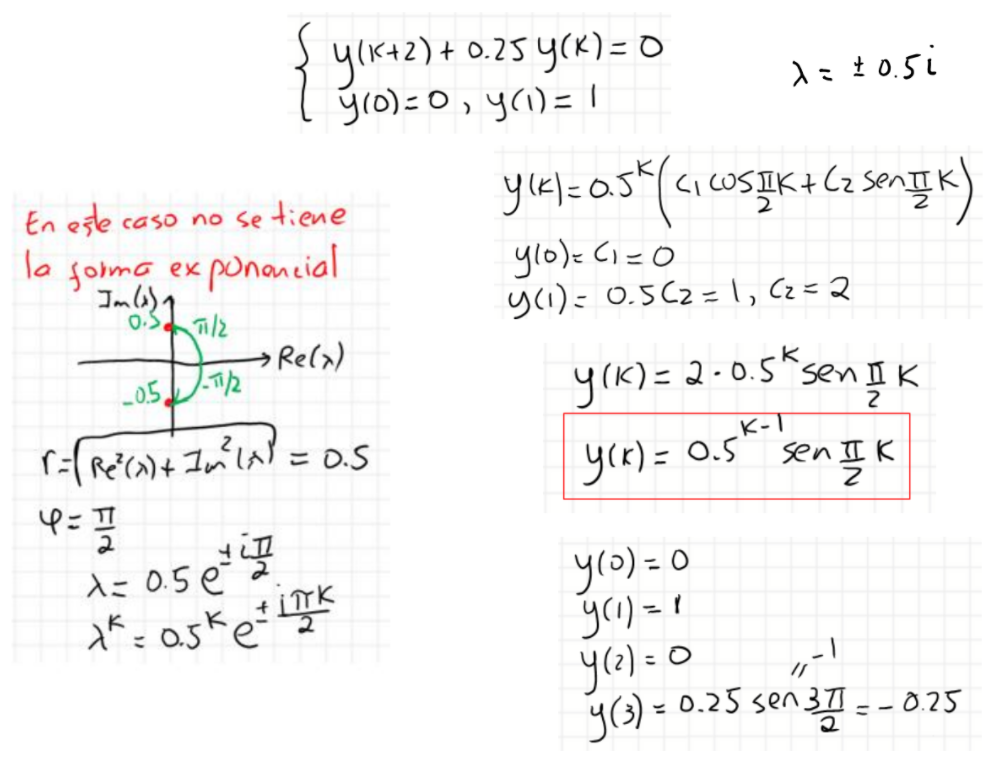

#### Tercer ejemplo de solución analítica: Ceros que no tienen sentido

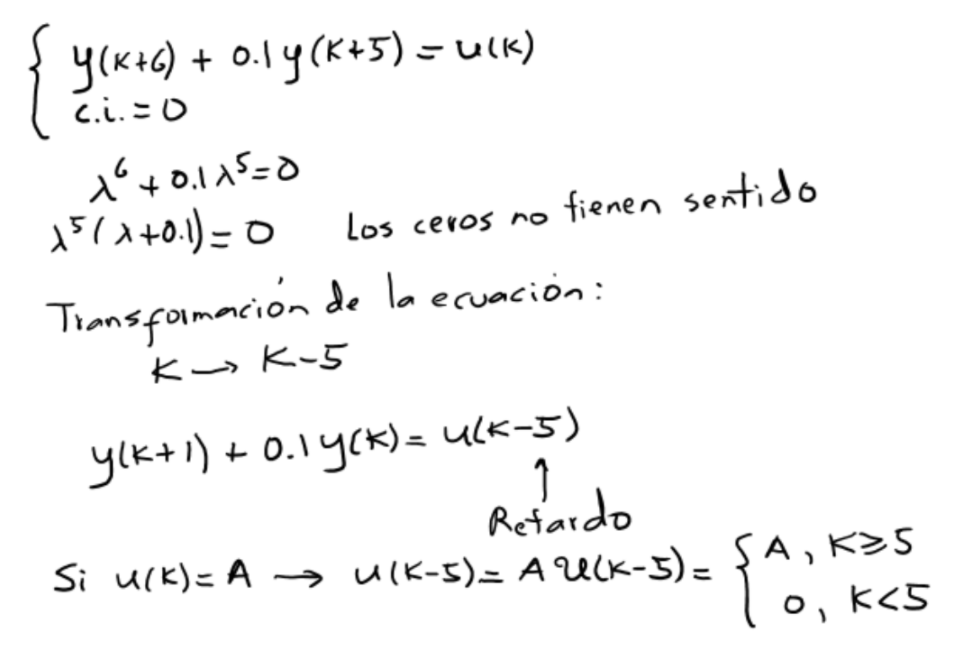

## Clase 4: Transformada de Laplace 

### Definición: Transformada de Laplace


$$L\left\lbrace f\left(t\right)\right\rbrace \equiv F\left(s\right)=\int_{0^- }^{\infty } e^{-\textrm{st}} f\left(t\right)\textrm{dt},\;s=\sigma +i\omega$$


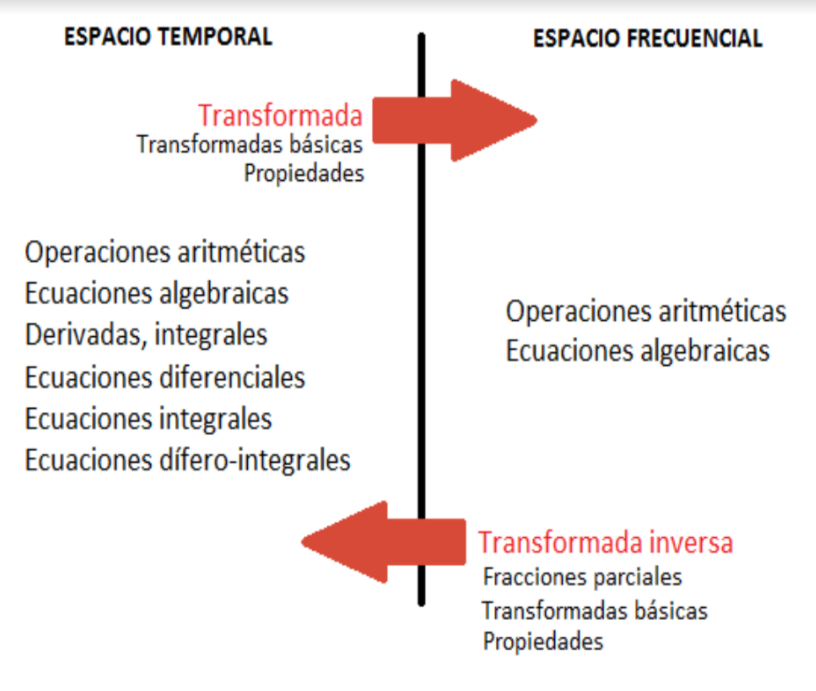

### Transformadas básicas transformada de Laplace

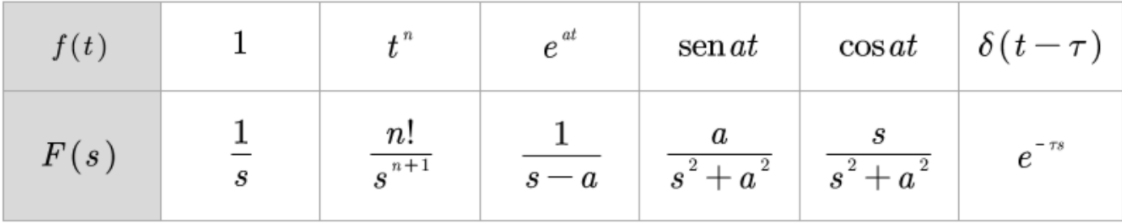

### Propiedades básicas transformada de Laplace

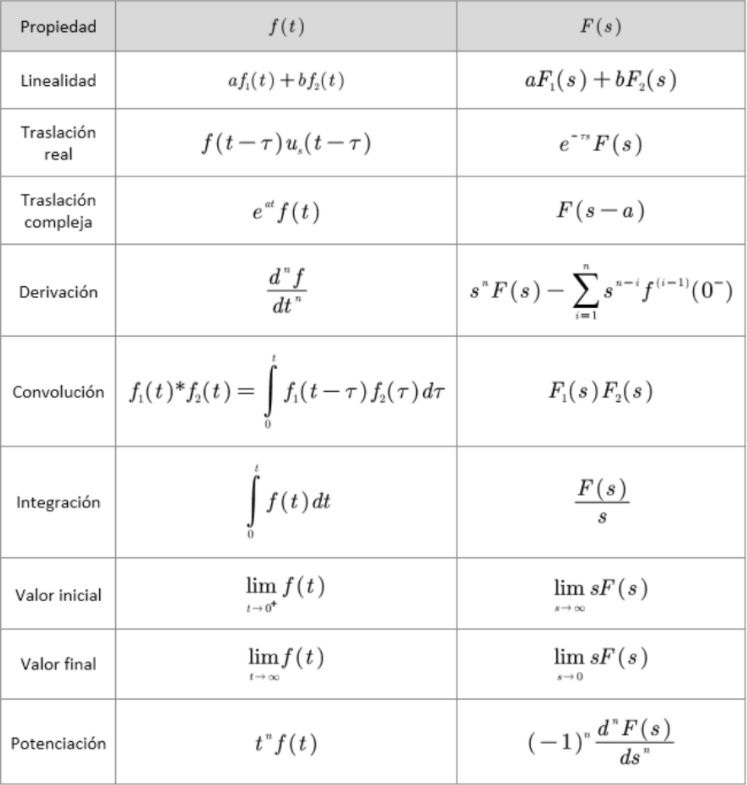

## Clases 5 y 6: Transformada Z

### Concepto de función muestreada

A partir de una función cualquiera $f\left(t\right),t\ge 0$, definiremos la función muestreada $\overset{\star }{f\left(t\right)}$ con intervalo de muestreo $T$ como se sigue


$$\overset{\star }{f\left(t\right)} =f\left(t\right)\sum_{k=0}^{\infty } \delta \left(t-\textrm{kT}\right)=\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)\delta \left(t-\textrm{kT}\right)$$


Debe ser claro que $\overset{\star }{f\left(t\right)} =\left\lbrace \begin{array}{ll}
f\left(t\right)\delta \left(t-\textrm{kT}\right) & t=\textrm{kT},\textrm{para}\;\textrm{algún}\;k=0,1,2,\ldotp \ldotp \ldotp \\
0 & \textrm{en}\;\textrm{otro}\;\textrm{caso}
\end{array}\right.$

### Transformada Z

Aplicando la transformada de Laplace a una función muestreada obtenemos que 

$L\left\lbrace \overset{\star }{f\left(t\right)} \right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)L\left\lbrace \delta \left(t-\textrm{kT}\right)\right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)e^{-\textrm{kTs}}$, ahora, haciendo el cambio de variable $z=e^{\textrm{Ts}}$, llegamos a que

$L\left\lbrace \overset{\star }{f\left(t\right)} \right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)z=Z\left\lbrace f\left(\textrm{kT}\right)\right\rbrace$, adicionalmente, sabiendo que T actúa como una variable muda se sigue que podemos asumir $T=1$ y considerar


$$Z\left\lbrace f\left(\textrm{kT}\right)\right\rbrace =$$

$$\sum_{k=0}^{\infty } f\left(k\right)z^{-k} =\Im \left(z\right)$$


#### Transformadas básicas

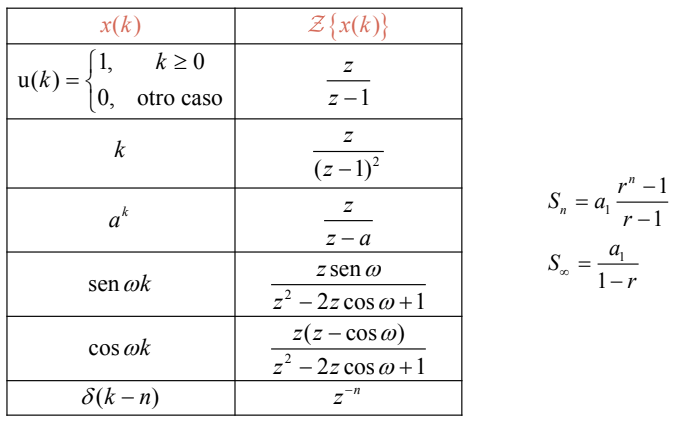

#### Propiedades operacionales

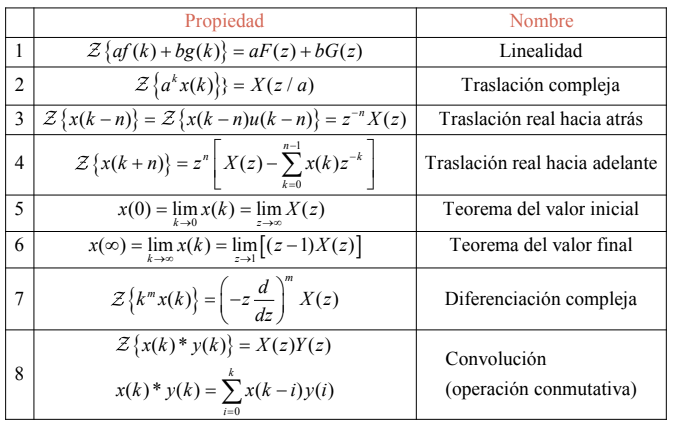

### Transformada Z inversa

Notando que la transformada Z de una función es una fracción propia, es posible calcular la transformada Z inversa mediante procedimientos:

- **Método de la serie infinita de potencias: **Se procede mediante división larga. Los coeficientes de la división corresponden con los valores de la función en cada instante de muestreo. $Y\left(z\right)=\frac{10z}{\left(z-1\right)\left(z-2\right)}=\frac{10z}{z^2 -3z+2}=10z^{-1} +30z^{-2} +70z^{-3} +\ldotp \ldotp \ldotp =\sum_{k=0}^{\infty } f\left(k\right)z^{-k} \Longrightarrow f\left(0\right)=0,f\left(1\right)=10,f\left(2\right)=30,f\left(3\right)=70,\ldotp \ldotp \ldotp$

- **Desarrollo en fracciones parciales: **Se debe garantizar que cada fracción parcial sea una función propia. De forma tal, buscamos reconocer estructuras a partir de las cuales aplicar la tabla de transformadas básicas y propiedades operacionales.

- **Integral de inversión: **Es posible calcular la transformada inversa por definición, sin embargo, será necesario resolver una integral compleja por el teorema del residuo de Cauchy. **Este método no se utiliza en clase.**

### Solución de ecuaciones en diferencias aplicando transformada Z en MatLab

Supongamos que queremos resolver la siguiente ecuación en diferencias sujeta a condiciones iniciales


$$\left\lbrace \begin{array}{ll}
y\left(k+3\right)+0\ldotp 8y\left(k+2\right)=0 & \\
y\left(0\right)=1,y\left(1\right)=0,y\left(2\right)=1 & 
\end{array}\right.$$


#### Solución mediante fracciones parciales

**Solución analítica**

clear;clc
%y(k+3)+0.8*y(k+2)==0 % y(0)=1, y(1)=0, and y(2)=1.
syms y(k) z %se declara la función simbólica y(k) y la variable simbólica z
assume(k>=0 & in(k,'integer')) % se establece que k es entero mayor o igual a 0
f = y(k+3)+0.8*y(k+2)==0 % se declara la ecuación en diferencias

$$f = \frac{4\,y\left(k+2\right)}{5}+y\left(k+3\right)=0$$

fZT = ztrans(f,k,z) %transformada z de la ecuación en diferencias, la variable k pasa a z

$$fZT = \frac{4\,z^{2}\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)}{5}-z\,y\left(2\right)-\frac{4\,z\,y\left(1\right)}{5}+z^{3}\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)-\frac{4\,z^{2}\,y\left(0\right)}{5}-z^{2}\,y\left(1\right)-z^{3}\,y\left(0\right)=0$$

syms pZT %variable para resolver la ecuación
fZT = subs(fZT,ztrans(y(k),k,z),pZT) % se sustituyen las expresiones de Y(z) por la variable simbólica pZT

$$fZT = \frac{4\,\mathrm{pZT}\,z^{2}}{5}-z\,y\left(2\right)-\frac{4\,z\,y\left(1\right)}{5}+\mathrm{pZT}\,z^{3}-\frac{4\,z^{2}\,y\left(0\right)}{5}-z^{2}\,y\left(1\right)-z^{3}\,y\left(0\right)=0$$

pZT = solve(fZT,pZT) % se soluciona la ecuación para pZT=Y(Z)

$$pZT = \frac{4\,y\left(1\right)+5\,y\left(2\right)+4\,z\,y\left(0\right)+5\,z\,y\left(1\right)+5\,z^{2}\,y\left(0\right)}{5\,z^{2}+4\,z}$$

pZT = subs(pZT,[y(0) y(1) y(2)],[1 0 1]) % se sustituyen los valores de las condiciones iniciales para obtener la fracción Y(z)

$$pZT = \frac{5\,z^{2}+4\,z+5}{5\,z^{2}+4\,z}$$

pZT=partfrac(pZT) % esta línea de código ayuda a evidenciar la descomposición en fracciones parciales

$$pZT = \frac{5}{4\,z}-\frac{25}{4\,\left(5\,z+4\right)}+1$$

ySol = iztrans(pZT,z,k) % se aplica la transformada inversa, la variable z pasa a k

$$ySol = \frac{5\,\delta_{k-1,0}}{4}+\frac{25\,{\left(-\frac{4}{5}\right)}^{k}}{16}-\frac{9\,\delta_{k,0}}{16}$$

ySol = simplify(ySol) % de ser posible se simplifica la expresión resultante, esta es la solución de la ecuación en diferencias

$$ySol = \frac{5\,\delta_{k-1,0}}{4}+\frac{25\,{\left(-\frac{4}{5}\right)}^{k}}{16}-\frac{9\,\delta_{k,0}}{16}$$

**Gráfica de la solución analítica**

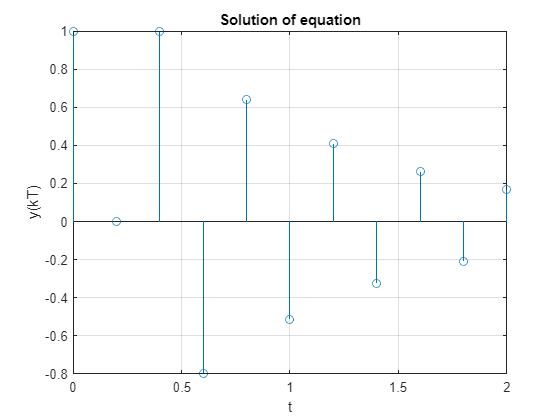

kValues = 0:10; %instantes de muestreo
T=0.2;% intervalo de muestreo
ySolValues = subs(ySol,k,kValues); %evaluamos los valores de k en la solución
ySolValues = double(ySolValues); % pasamos los valores de simbólico a variable numérica
ySolValues = real(ySolValues); % capturamos la parte real de los valores
figure(1)
clf
stem(kValues*T,ySolValues) %gráfica de la función discretizada
title('Solution of equation')
xlabel('t')
ylabel('y(kT)')
grid on

#### Solución mediante la serie infinita de potencias

Para resolver la ecuación mediante la serie infinita de potencias debemos aplicar la transformada Z y llegar a la expresión racional $Y\left(z\right)=\frac{P_1 \left(z\right)}{P_2 \left(z\right)}$. Para el caso del ejemplo que estamos resolviendo tenemos que $Y\left(z\right)=\frac{5z^2 +4z+5}{5z^2 +4z}$. Podemos aplicar la división larga para obtener los primeros 11 valores de la función (equivalentes a los puntos de la gráfica anterior) mediante la función [ldiv](https://www.mathworks.com/matlabcentral/fileexchange/1752-calculates-inverse-z-transform-by-long-division) desarrollada por Tamer Melik. El primer argumento que recibe esta función son los coeficientes del numerados, luego los coeficientes del denominador y finalmente el número de valores de la función por obtener

yvals=ldiv([5,4,5],[5,4],11)

yvals =     1.0000         0    1.0000   -0.8000    0.6400   -0.5120    0.4096   -0.3277    0.2621   -0.2097    0.1678


## Clases 7 y 8: Introducción a las funciones de transferencia

### Definición de la función de transferencia

Cuando aplicamos la transformada de Laplace a un problema de valores iniciales no homogéneo 


$$\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\cdots +a_n y=u\left(t\right) & \\
y\left(0\right)=y_0 ,\overset{\cdot }{y} \left(0\right)=y_1 ,\cdots ,\overset{\left(n-1\right)}{y\left(0\right)} =y_{n-1}  & 
\end{array}\right.$$


obtenemos una expresión de la forma


$$\begin{array}{l}
s^n Y\left(s\right)-s^n \sum_{k=1}^n s^{-k} \overset{\left(k-1\right)}{y\left(0^- \right)} +a_1 \left(s^{n-1} Y\left(s\right)-s^{n-1} \sum_{k=1}^{n-1} s^{-k} \overset{\left(k-1\right)}{y\left(0^- \right)} \right)+\cdots +a_{n-1} \left(\textrm{sY}\left(s\right)-y\left(0^- \right)\right)+a_n Y\left(s\right)=U\left(s\right)\\
\Longrightarrow Y\left(s\right)\left(s^n +a_1 s^{n-1} +\cdots +a_n \right)-s^{n-1} y\left(0^- \right)-s^{n-2} \left(a_1 y\left(0^- \right)+\overset{\cdot }{y\left(0^- \right)} \right)-\cdots -s\left(\overset{\left(n-2\right)}{y\left(0^- \right)} +\overset{\left(n-3\right)}{a_1 y\left(0^- \right)} +\cdots +a_{n-2} y\left(0^- \right)\right)-\left(\overset{\left(n-1\right)}{y\left(0^- \right)} +\cdots +a_{n-1} y\left(0^- \right)\right)=U\left(s\right)\\
\Longrightarrow Y\left(s\right)P_{\textrm{ch}} \left(s\right)-{b_1 s}^{n-1} -b_2 s^{n-2} -\cdots -b_{n-1} s-b_n =U\left(s\right)\\
\Longrightarrow Y\left(s\right)P_{\textrm{ch}} \left(s\right)-P_{\textrm{ci}} \left(s\right)=U\left(s\right)\\
\Longrightarrow Y\left(s\right)=\frac{P_{\textrm{ci}} \left(s\right)}{P_{\textrm{ch}} \left(s\right)}+\frac{U\left(s\right)}{P_{\textrm{ch}} \left(s\right)}
\end{array}$$


Adicionalmente, si la entrada fuera de la forma $c_0 \overset{\left(m\right)}{u} +c_1 \overset{\left(m-1\right)}{u} +\cdots +c_n u,\;m\le n$, llegaríamos a que 


$$Y\left(s\right)=\frac{P_{\textrm{ci}} \left(s\right)}{P_{\textrm{ch}} \left(s\right)}+\frac{P_u \left(s\right)}{P_{\textrm{ch}} \left(s\right)}U\left(s\right)$$


Donde $P_{\textrm{ch}} \left(s\right)$ es el polinomio característico de la ecuación diferencial homogénea en la variable $s$, $P_{\textrm{ci}} \left(s\right)$ es un polinomio generado a partir de las condiciones iniciales y $P_u \left(s\right)$ es un polinomio generado a partir de las derivadas de la entrada (las condiciones iniciales de la entrada se asumen iguales a 0). De la última expresión que obtuvimos podemos observar que la solución de la ecuación diferencial no homogénea viene dada por una respuesta a las condiciones iniciales $\frac{P_{\textrm{ci}} \left(s\right)}{P_{\textrm{ch}} \left(s\right)}$ y una respuesta a la entrada $\frac{U\left(s\right)}{P_{\textrm{ch}} \left(s\right)}$. Es decir, la solución de la ecuación se compone de la suma de la solución a la ecuación asociada homogénea y una solución particular con condiciones iniciales nulas. 

De la naturaleza de la transformada de Laplace se sigue que $\deg \left\lbrace P_{\textrm{ch}} \left(s\right)\right\rbrace >\deg \left\lbrace P_{\textrm{ci}} \left(s\right)\right\rbrace$ y que $\deg \left\lbrace P_{\textrm{ch}} \left(s\right)\right\rbrace \ge \deg \left\lbrace P_u \left(s\right)\right\rbrace$.

Para el caso discreto, de manera análoga, la solución mediante transformada Z de la ecuación en diferencias no homogénea con condiciones iniciales


$$\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_1 y\left(k+n-1\right)+\cdots +a_n y\left(k\right)=u\left(k+m\right)+\cdots +u\left(k\right) & m\le n\\
y\left(0\right)=y_0 ,\;y\left(1\right)=y_1 ,\cdots ,y\left(n-1\right)=y_{n-1}  & 
\end{array}\right.$$


nos lleva a la forma


$$Y\left(z\right)=\frac{P_{\textrm{ci}} \left(z\right)}{P_{\textrm{ch}} \left(z\right)}+\frac{P_u \left(z\right)}{P_{\textrm{ch}} \left(z\right)}U\left(z\right)$$


Y de la naturaleza de la transformada Z se sigue que $\deg \left\lbrace P_{\textrm{ch}} \left(z\right)\right\rbrace \ge \deg \left\lbrace P_{\textrm{ci}} \left(z\right)\right\rbrace$ y que $\deg \left\lbrace P_{\textrm{ch}} \left(z\right)\right\rbrace \ge \deg \left\lbrace P_u \left(z\right)\right\rbrace$.

Se hace de particular relevancia, el caso en el que las condiciones iniciales son nulas $\left(P_{\textrm{ci}} \left(s/z\right)=0\right)$ puesto que la expresión para $Y\left(s/z\right)$ se torna de la forma


$$Y\left(s/z\right)=\frac{P_u \left(s/z\right)}{P_{\textrm{ch}} \left(s/z\right)}U\left(s/z\right)\Longrightarrow \frac{Y\left(s/z\right)}{U\left(s/z\right)}=\frac{P_u \left(s/z\right)}{P_{\textrm{ch}} \left(s/z\right)}$$


A la expresión $\frac{P_u \left(s/z\right)}{P_{\textrm{ch}} \left(s/z\right)}$ se le conoce como **función de transferencia **$G\left(s/z\right)$ del sistema de ecuaciones diferenciales / en diferencias. La función de transferencia es de particular relevancia para el área de sistemas dinámicos, donde podemos resignificar cada componente de la expresión anterior en términos de una planta/proceso/sistema (dado por $G\left(s/z\right)$), un conjunto de señales de entrada que se aplican al sistema ($U\left(s/z\right)$), un conjunto de estados del sistema ($X\left(s/z\right)$) y un conjunto de salidas del sistema ($Y\left(s/z\right)$). **El tema de los estados del sistema será abordado más adelante.** Lo anterior, nos permite representar el anterior problema matemático de la forma

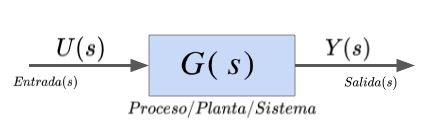

En este orden de ideas, la **función de transferencia** es una **caraterización completa del sistema** que nos permite **determinar la salida del sistema para cualquier entrada que se le aplique. **En términos matemáticos, esto puede verse al notar que $Y\left(s/z\right)=G\left(s/z\right)U\left(s/z\right)$. Es decir que si conocemos la función de transferencia del sistema y la entrada que se le aplica, podemos calcular la salida mediante transformada inversa o convolución.

En general, el concepto de función de transferencia también es aplicable a cualquier sistema en estado estacionario (sin variaciones) aunque las condiciones de dicho estado no sean nulas. Para ello, basta trabajar con las variables incrementales $\left(\Delta U\left(s\right),\Delta Y\left(s\right)\right)$. Es decir, obtenemos el cambio que experimenta la salida del sistema al modificar la entrada en estado estacionario y luego adicionamos el valor de la salida en estado estacionario para obtener el comportamiento del sistema, tal y como se ejemplifica en el siguiente diagrama:

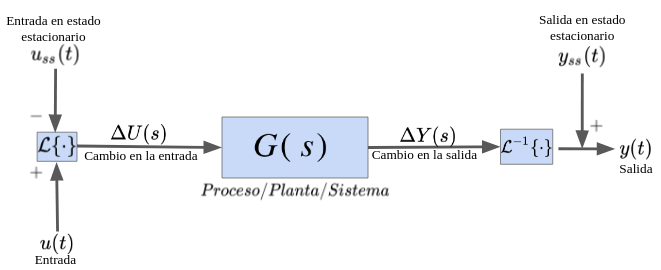

### Conceptos claves

- **Polos: **Son los ceros del polinomio característico $P_{\textrm{ch}} \left(s/z\right)$, por tanto, son los valores de $s/z$ para los cuales la función de transferencia tiende a infinito. Los polos determinan la estabilidad del sistema. Para el caso continuo, si todos los polos se encuentran en el semiplano izquierdo del plano $s$ se sigue que el sistema será estable. Para el caso discreto, un sistema será estable si todos los polos se encuentran dentro del círculo unitario del plano $z$.

- **Ceros finitos: **Son los ceros del polinimio de la entrada $P_u \left(s/z\right)$, por tanto, son los valores de $s/z$ para los cuales la función de transferencia tiende a cero. Los ceros nos permiten identificar entradas que son anuladas por el sistema e intuir ciertos comportamientos del sistema, tal y como se verá más adelante.

- **Orden: **Es el grado de $P_{\textrm{ch}} \left(s/z\right)$, dicho grado nos habla del orden de la ecuación diferencial asociada al sistema.

- **Orden relativo: **$\deg \left\lbrace P_{\textrm{ch}} \left(z\right)\right\rbrace -\deg \left\lbrace P_u \left(z\right)\right\rbrace$. El orden relativo nos habla sobre el retardo del sistema para el caso discreto. Este tema se abordará con más profundidad en la siguiente clase.

- **Polos dominantes: **Polos estables cercanos al eje imaginario (caso continuo). Polos estables cercanos al círculo unitario (caso continuo). Debido a dicha cercanía, estos polos son los que más determinan el comportamiento del sistema.

- **Polos insignificantes: **Polos alejados del polo más dominante. Se calcula que un polo ajelado más de 5 veces del polo dominante podría ser insignificante. Un polo alejado más de 10 veces del polo dominante se juzga insignificante. Los polos insignificantes aportan muy poco a la dinámica del sistema.

- **Ecuación característica: **$P_{\textrm{ch}} \left(\lambda \right)$.

## Clases 9 y 10: Funciones de transferencia

### Retardos y orden relativo

Las transformadas para una señal continua con retardo son de la forma


$$\left\lbrace \begin{array}{ll}
L\left\lbrace f\left(t-\tau \right)u_s \left(t-\tau \right)\right\rbrace =e^{-\tau s} F\left(s\right) & u_s \left(t-\tau \right)=\left\lbrace \begin{array}{ll}
0 & t<\tau \\
1 & t\ge \tau 
\end{array}\right.\\
Z\left\lbrace f\left(k-d\right)u_s \left(k-d\right)\right\rbrace =z^{-d} F\left(z\right) & u_s \left(k-d\right)=\left\lbrace \begin{array}{ll}
0 & k<d\\
1 & k\ge d
\end{array}\right.
\end{array}\right.$$


Por tanto, un problema como el siguiente


$$\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\cdots +a_n y=c_0 \overset{\left(m\right)}{u} \left(t-\tau \right)u_s \left(t-\tau \right)+\cdots +c_m u\left(t-\tau \right)u_s \left(t-\tau \right) & m\le n\\
y\left(0\right)=\overset{\cdot }{y} \left(0\right)=\cdots =\overset{\left(n-1\right)}{y\left(0\right)} =0 & 
\end{array}\right.$$


conduce a la solución


$$\frac{Y\left(s\right)}{U\left(s\right)}=e^{-\tau s} \frac{P_u \left(s\right)}{P_{\textrm{ch}} \left(s\right)}=G\left(s\right)$$


mientras que un problema como


$$\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_1 y\left(k+n-1\right)+\cdots +a_n y\left(k\right)=u\left(k+m-d\right)u_s \left(k-d\right)+\cdots +u\left(k-d\right)u_s \left(k-d\right) & m\le n\\
y\left(0\right)=\;y\left(1\right)=\cdots =y\left(n-1\right)=0 & 
\end{array}\right.$$


conduce a la solución


$$\frac{Y\left(z\right)}{U\left(z\right)}=z^{-d} \frac{P_u \left(z\right)}{P_{\textrm{ch}} \left(z\right)}=\frac{P_u \left(z\right)}{{z^d P}_{\textrm{ch}} \left(z\right)}=G\left(z\right)$$


Por tanto, la presencia de exponenciales, en el caso continuo, o la presencia de polos en $z=0$, en el caso discreto, nos alertan sobre la presencia de retardos en el sistema. Para el caso continuo los retardos son bastante intuitivos mientras que el caso discreto requiere un poco más de atención. En primer lugar, ya no podremos interpretar inmediatamente que el denominador de la función de transferencia corresponde con el polinomio característico de la ecuación en diferencias asociada al sistema. Para determinar el polinomio característico tendremos que factorizar, de ser posible, el denominador, hasta que obtengamos una expresión de la forma

 
$$\underset{\textrm{Retardo}}{\underbrace{z^{-d} } } \underset{\textrm{Polinomio}\;\textrm{característico}}{\underbrace{\left(z^n +a_1 z^{n-1} +\cdots +a_n \right)} } ,a_n \not= 0$$


**Ecuación en diferencias a partir de la función de transferencia**

Partamos de un sistema con la función de transferencia $G\left(z\right)=\frac{z}{z^2 -0\ldotp 25}$, dado que cuando trabajamos con funciones de transferencia asumimos que las condiciones iniciales son iguales a 0, se sigue que la ecuación en diferencias debe ser de la forma $\left\lbrace \begin{array}{ll}
y\left(k+2\right)-0\ldotp 25y\left(k\right)=u\left(k+1\right) & \\
y\left(0\right)=y\left(1\right)=0 & 
\end{array}\right.$. Ahora, hagamos $u\left(t\right)=u_s \left(t\right)$ y solucionemos este sistema empleando MatLab

clear;clc
G = tf([1 0],[1 0 0.25],1)

G =
 
      z
  ----------
  z^2 + 0.25
 
Sample time: 1 seconds
Discrete-time transfer function.



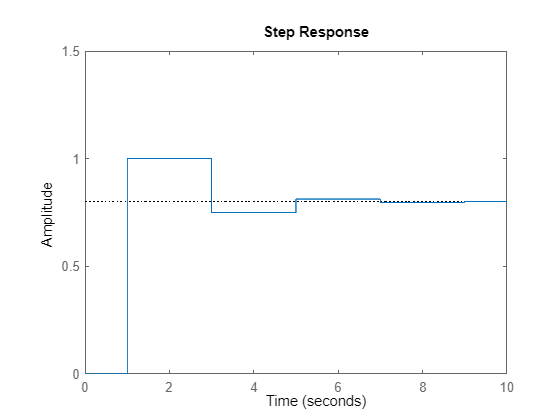

figure(1)
clf
step(G)
xlim([0 10])
ylim([0 1.5])

Sin embargo, debemos notar que MatLab toma un valor distinto de 0 para $y\left(1\right)$. Para entender porqué sucede esto, podemos modificar la función de transferencia para obtener la ecuación en diferencias hacia atrás


$$G\left(z\right)=\frac{z^{-2} }{z^{-2} }G\left(z\right)=\frac{z^{-1} }{1-0\ldotp 25z^{-2} }\Longrightarrow \left\lbrace \begin{array}{ll}
y\left(k\right)-0\ldotp 25y\left(k-2\right)=u\left(k-1\right) & \\
y\left(m\right)=0 & m<0
\end{array}\right.$$


En este caso, podemos resolver $y\left(1\right)=0\ldotp 25y\left(-1\right)+u\left(0\right)=1$, que coincide con la gráfica entregada por MatLab. 

**El orden relativo revisitado**

Del ejemplo anterior podemos empezar a intuir el efecto del orden relativo, para el caso discreto, en el comportamiento del sistema. De hecho, **el orden relativo de la función de transferencia es equivalente al retardo que presenta el sistema**. Esto puede comprobarse cuando determinamos la ecuación en diferencias hacia atrás. Por ejemplo:


$$G\left(z\right)=\frac{z^2 }{z^2 -0\ldotp 25}=\frac{z^{-2} }{z^{-2} }\frac{z^2 }{z^2 -0\ldotp 25}=\frac{1}{1-0\ldotp 25z^{-2} }\Longrightarrow \left\lbrace \begin{array}{ll}
y\left(k\right)-0\ldotp 25y\left(k-2\right)=u\left(k\right) & \\
y\left(m\right)=0 & m<0
\end{array}\right.$$


Notemos que el orden relativo de esta ecuación en diferencias es 0 y que $y\left(0\right)=0\ldotp 25y\left(-2\right)+u\left(k\right)=1$, que coincide con la solución de MatLab

G = tf([1 0 0],[1 0 0.25],1)

G =
 
     z^2
  ----------
  z^2 + 0.25
 
Sample time: 1 seconds
Discrete-time transfer function.



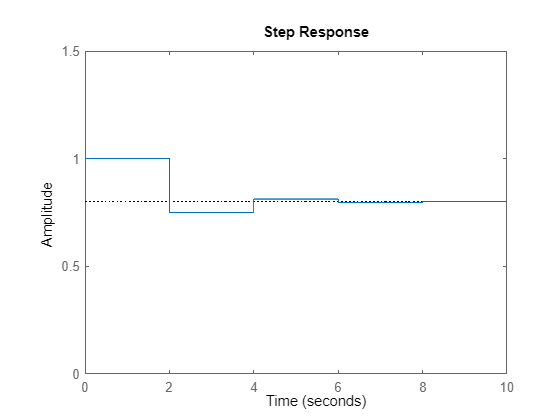

figure(2)
clf
step(G)
xlim([0 10])
ylim([0 1.5])

### Sistemas de fase no mínima

#### El efecto de los ceros de la función de transferencia

Diremos que un sistema es de **fase no mínima** cuando tiene al menos un **cero finito por fuera de la región de estabilidad **en el plano S o Z, según sea el caso. Los sistemas de fase no mínima presentan  comportamientos poco intuitivos debido al efecto de los ceros. En la sección anterior vimos cómo podíamos deducir la ecuación diferencial/diferencias a partir de la función de transferencia. Podemos notar que el componente $P_u \left(s/z\right)$ determina la forma de la entrada para la ecuación diferencial/diferencias, es decir, el numerador de la función de transferencia afecta a la entrada del sistema. Pensemos, por ejemplo, en una función de transferencia dada por $G=\frac{s}{P_{\textrm{ch}} \left(s\right)}$, la presencia de $s$ en el numerador sugiere que la entrada que se aplique al sistema será derivada, ¿qué sucedería entonces si a este sistema la aplicamos una entrada constante $u\left(t\right)=u_s \left(t\right)$? Veámoslo mediante simulación

clear;clc;close all
G=zpk(0,[-1 -2 -3],1)

G =
 
          s
  -----------------
  (s+1) (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



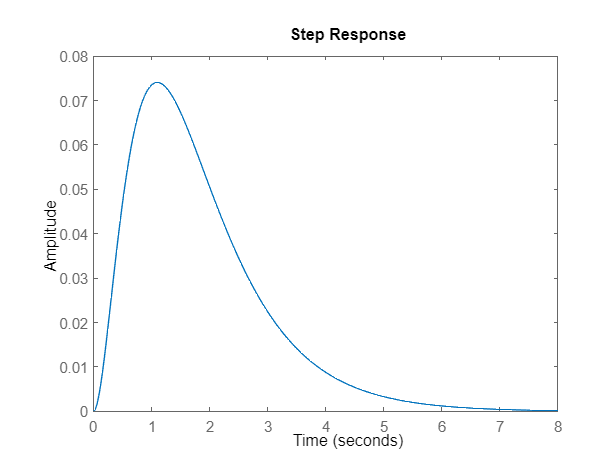

figure(1)
clf
step(G)

Vemos entonces que nuestro sistema tiene una reacción inicial al aplicar la entrada pero luego se estabiliza en 0, a pesar de que la entrada no es nula. ¿Qué ha pasado entonces? ¡La entrada ha sido anulada por el cero de la función de transferencia! Para analizar este proceso matemáticamente, primero veamos la forma de la ecuación diferencial que correspondería con este problema

tf(G)

ans =
 
            s
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.



$\overset{\ldotp \ldotp \ldotp }{y} +6\;\overset{\ldotp \ldotp }{y} +11\overset{\ldotp }{y} +6y=\overset{\ldotp }{u}$. Ahora bien, considerando que la entrada del sistema es el escalón, tenemos que $\overset{\ldotp }{u} =0$ y por tanto la ecuación correspondiente es $\overset{\ldotp \ldotp \ldotp }{y} +6\;\overset{\ldotp \ldotp }{y} +11\overset{\ldotp }{y} +6y=0$, cuya solución corresponde con el valor de estabilización de la simulación. Sin embargo, se aprecia una dinámica al principio de la simulación que no corresponde con la la ecuación diferencial que hemos hallado. Esto se debe a que $\overset{\ldotp }{u} \left(t\right)=\left\lbrace \begin{array}{ll}
0 & t>0\\
\delta \left(0\right) & t=0
\end{array}\right.$. Visto desde la perspectiva de las funciones de transferencia, el problema que estamos resolviendo toma la forma $Y\left(s\right)=G\left(s\right)U\left(s\right)=\frac{s}{s^3 +6s^2 +11s+6}\times \frac{1}{s}=\frac{1}{s^3 +6s^2 +11s+6}$, resta notar que $1=L^{-1} \left\lbrace \delta \left(0\right)\right\rbrace$ para que ambos resultados sean coherentes. Ahora bien, podemos continuar con la solución para $y\left(t\right)$ haciendo fracciones parciales y aplicando transformada inversa

[r,p,k] = residue(1,[1 6 11 6])

r =     0.5000
   -1.0000
    0.5000


p =    -3.0000
   -2.0000
   -1.0000



k =

     []




$$Y\left(s\right)=\frac{1}{s^3 +6s^2 +11s+6}=\frac{1}{2\left(s+3\right)}-\frac{1}{s+2}+\frac{1}{2\left(s-1\right)}\Longrightarrow y\left(t\right)=\frac{1}{2}e^{-3t} -e^{-2t} +\frac{1}{2}e^{-t}$$


Este resultado debe coincidir con la respuesta al impulso para la función de transferencia $G_2 =\frac{1}{s^3 +6s^2 +11s+6}$. Veamos

G2=tf(1,[1 6 11 6])

G2 =
 
            1
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.



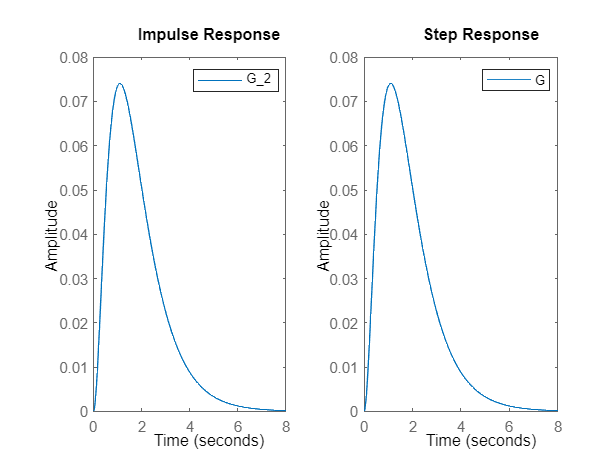

figure(2)
clf
subplot(1,2,1)
impulse(G2)
legend('G_2')
subplot(1,2,2)
step(G)
legend('G')

En conclusión, el cero de la función de transferencia actúa anulando la entrada que se le aplica al sistema pero dicha anulación no ocurre inmediatamente dado que en el instante inicial aparece un impulso. Lo particularmente interesante de este resultado es que los sistemas de **fase no mínima **pueden **anular** **entradas** que **divergen asintóticamente**, haciendo que el sistema siga convergiendo. En este orden de ideas, un sistema con los siguientes ceros $P_u \left(s\right)=0\Longrightarrow s\in \left\lbrace 0,-1,2,\pm 3i,3\pm 4i\right\rbrace$ anulará entradas de la forma $\left\lbrace k,e^{-t} ,e^{2t} ,\textrm{cos3t},\textrm{sin3t},e^{\left(3\pm 4i\right)t} \;\right\rbrace$.

#### Comportamiento de un sistema de fase no mínima

Además de las propiedades mencionadas anteriormente, los sistemas de fase no mínima tienen comportamientos interesantes. Si bien el nombre de **fase no mínima** corresponde a dinámicas que se observan en el análisis en frecuencia de estos modelos, una forma rápida de entender dicho nombre es pensando que su comportamiento es más rico en términos de la fase, es decir, del ángulo, es decir, más ricos en términos de dinámica. Algo que se observa con frecuencia en estos modelos, es que al aplicarles una entrada reaccionan primero en el sentido opuesto al esperado, aunque luego se comporten de forma esperada. Tal comportamiento hace que sea especialmente difícil diseñar un control para estos sistemas. Algunos ejemplos cotidianos de sistemas de fase no mínima son:

- Un avión entendido como un sistema con **entrada** de **ángulo de ataque **y **salida** de **altitud**. En este caso, cuando un piloto desea ganar altura debe aumentar el ángulo de ataque apuntando la aeronave hacia arriba, sin embargo, el centro de gravedad de la aeronave se desplaza y ésta pierde altitud antes de empezar a ganarla.

- Un organismo superior entendido como un sistema cuya **entrada** son los **alimentos** **que** **consume** y la **salida** es el **nivel** **de** **energía** en el organismo. En este caso, los organismos deben gastar energía para descomponer los alimentos en moléculas simples de las cuales puede extraerse energía, es decir, primero el nivel de energía decae y luego aumenta.

- Una empresa entendida como un sistema cuya **entrada** es el **número** de **nuevos** **empleados** que se contratan y la **salida** es la **productividad** de la empresa. En este caso, al contratar un nuevo empleado es necesario dedicar del tiempo de trabajo de otros empleados para enseñar las nuevas tareas, esto ocasiona un descenso en la productividad que luego aumenta cuando el nuevo empleado aprende sus labores.

Veamos la respuesta a una entrada de tipo escalón para algunos sistemas de fase no mínima. Primero, analicemos un modelo con $P_u \left(3\right)=0$. En este caso, vemos que aunque estamos aplicando una entrada positiva, el sistema responde disminuyendo su valor en estado de equilibrio (esto se debe al efecto del numerador de la función de transferencia $s-3$, que puede entenderse como derivar la entrada y luego restarle 3 veces el valor de la entrada. Notemos que el sistema muestra una ganancia al principio de la simulación.

clear;clc
G=zpk([3],[-1 -1.5 -2],1);
tf(G)

ans =
 
            s - 3
  -------------------------
  s^3 + 4.5 s^2 + 6.5 s + 3
 
Continuous-time transfer function.



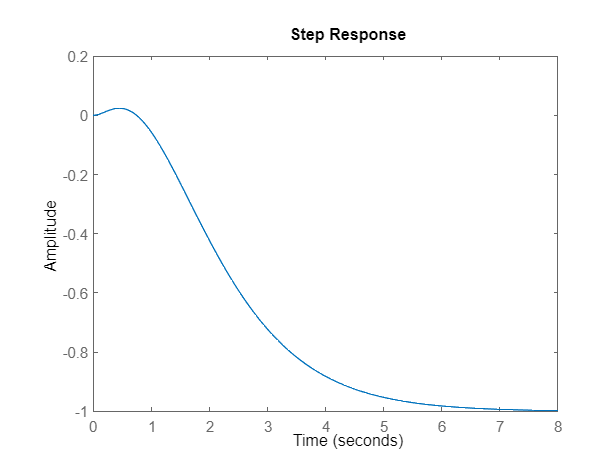

figure(3)
clf
step(G)

 Aumentemos ahora el número de ceros del sistema

G2=zpk([3 2],[-1 -1.5 -2],1);
tf(G2)

ans =
 
        s^2 - 5 s + 6
  -------------------------
  s^3 + 4.5 s^2 + 6.5 s + 3
 
Continuous-time transfer function.



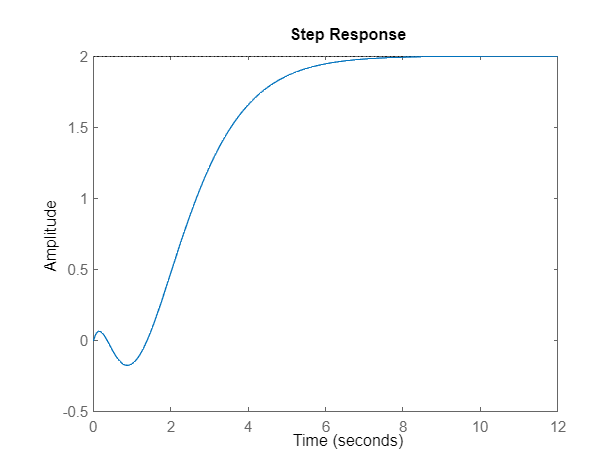

figure(4)
clf
step(G2)

En este caso, el sistema presenta una oscilación al inicio de la dinámica. Podría pensarse que hay presencia de valores propios imaginarios pero no es el caso. El sistema se estabiliza ahora en un valor mayor al que tenía en estado estacionario (puede hacerse el mismo análisis del caso anterior para comprender por qué). Notamos entonces que la presencia de ceros de fase no mínima enriquece la dinámica del sistema. Podemos comprobar tal afirmación simulando un sistema con el mismo polinomio característico pero de fase mínima

G3=zpk([-3 -4],[-1 -1.5 -2],1);
tf(G3)

ans =
 
       s^2 + 7 s + 12
  -------------------------
  s^3 + 4.5 s^2 + 6.5 s + 3
 
Continuous-time transfer function.



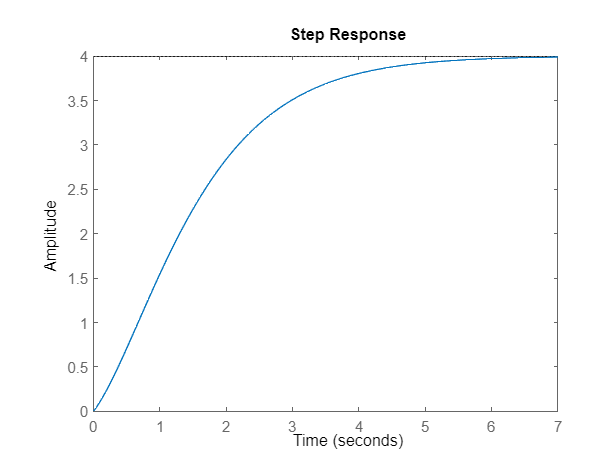

figure(5)
clf
step(G3)

### Reducción de orden

En general, es posible aproximar un modelo de orden superior con uno de menor orden que conserve sus principales características. Existen varios métodos formales de reducción de orden pero en este curso nos concentraremos en el método** de cancelación de polos y ceros de fase mínima **y el método de **eliminación de polos insignificantes**. Estos métodos explotan propiedades matemáticas intuitivas de la estructura de la función de transferencia para eliminar polos y luego compensar dicha eliminación con una ganancia , de forma que se conserve el valor de estabilización del sistema ante una entrada escalón. Para esta última parte, basta recordar que 


$$\lim_{t\longrightarrow \infty } y\left(t\right)=\lim_{s\longrightarrow 0} \textrm{sY}\left(s\right)=\lim_{s\longrightarrow 0} \textrm{sG}\left(s\right)U\left(s\right)=\lim_{s\longrightarrow 0} \textrm{sG}\left(s\right)\frac{1}{s}=G\left(0\right)$$



$$\lim_{k\longrightarrow \infty } y\left(k\right)=\lim_{z\longrightarrow 1} \left(z-1\right)Y\left(z\right)=\lim_{z\longrightarrow 1} \left(z-1\right)G\left(z\right)U\left(z\right)=\lim_{z\longrightarrow 1} \left(z-1\right)G\left(z\right)\frac{z}{z-1}=G\left(1\right)$$


#### Cancelación de polos y ceros de fase mínima

Pensemos que tenemos una función de transferencia con un polo y un cero cercanos


$$G\left(s\right)=G_1 \left(s\right)\frac{s+a\pm \Delta a}{s+a}=G_1 \left(s\right)\left\lbrack 1+\frac{\Delta a}{s+a}\right\rbrack ,\;\;\Delta a<<1$$


Para notar cuándo podemos decir que $G\left(s\right)\approx G_1 \left(s\right)$ debemos ver que

$L^{-1} \left\lbrace G\left(s\right)\right\rbrace =g\left(t\right)=g_1 \left(t\right)*\left\lbrack \delta \left(t\right)+\Delta {\textrm{aL}}^{-1} \left\lbrace \frac{1}{s+a}\right\rbrace \right\rbrack =g_1 \left(t\right)*\left\lbrack \delta \left(t\right)+\Delta {\textrm{ae}}^{-\textrm{at}} \right\rbrack$.

De este resultado podemos concluir que el único caso en el que es posible cancelar el polo y el cero ocurre cuando el polo se encuentra en la región de estabilidad, es decir, $a>0$. Por otro lado, la similitud entre $G\left(s\right)$ y $G_1 \left(s\right)$ dependerá de la cercanía a 0 de la diferencia entre el polo y el cero $\left(\Delta a\right)$ y de velocidad con la que el término desaparece $\left(e^{-\textrm{at}} \right)$. El caso discreto es análogo al continuo, se concluye que el polo debe estar dentro de la región de estabilidad. Ahora bien, cancelar un polo y un cero cuando el polo es estable y el cero se encuentra fuera de la región de estabilidad, causaría que un sistema de fase no mínima se convirtiera en uno de fase mínima, lo cual no tiene mucho sentido.

#### Eliminación de polos insignificantes

De las secciones anteriores, sabemos que un polo es insignificante cuando es estable y está alejado de 5-10 veces o más del polo dominante (en norma). Pensemos entonces en una función de transferencia estable con un polo insignificante $s=-a$ de la forma

$G\left(s\right)=\frac{P_u \left(s\right)}{P_{\textrm{aux}} \left(s\right)\left(s+b\right)\left(s+a\right)},||-a+b||>5||-b||$, siendo $d\left(\cdot ,\cdot \right)$  la métrica inducida por la norma euclídea. Sabemos que es posible plantear una descomposición en fracciones parciales de la forma

$G\left(s\right)=\frac{P_{G_1 } \left(s\right)}{P_{\textrm{aux}} \left(s\right)\left(s+b\right)}+\frac{A}{s+a}=G_1 \left(s\right)+\frac{A}{s+a}\approx G_1 \left(s\right)$. Ahora bien, la eliminación se basa en que la contribución de ${\textrm{Ae}}^{-\textrm{at}}$ es despreciable con relación al resto de términos que aparecen en la descomposición de fracciones parciales. También es posible proponer que $G\left(s\right)=\frac{P_u \left(s\right)}{P_{\textrm{aux}} \left(s\right)\left(s+b\right)\left(s+a\right)}\approx \frac{P_u \left(s\right)}{P_{\textrm{aux}} \left(s\right)\left(s+b\right)}=G_1 \left(s\right)$, siempre y cuando la fracción siga siendo propia.

#### Ejemplos de reducción de orden

**Ejemplo 1**

Supongamos que tenemos la siguiente función de transferencia

clear;clc
syms s
G=zpk([-3 -4],[-1 -10 -2],1)
figure(1)
clf
step(G)

En primer lugar, podemos plantear que $G\left(s\right)\approx \frac{\left(s+3\right)\left(s+4\right)}{\left(s+1\right)\left(s+2\right)}k=G_1 \left(s\right)$, donde $G\left(0\right)=0\ldotp 6=G_1 \left(0\right)=6k\Longrightarrow k=\frac{1}{10}$, es decir que $G_1 \left(s\right)=\frac{1}{10}\frac{\left(s+3\right)\left(s+4\right)}{\left(s+1\right)\left(s+2\right)}$. Pero también podríamos emplear una construcción más elaborada calculando las fracciones parciales de $G\left(s\right)$

f=(s+3)*(s+4)/(s^3+13*s^2+32*s+20)
partfrac(f)

En este punto, despreciamos la fracción paracial que queremos remover y reconstruimos la expresión con orden reducido

expre=simplify(partfrac(f)-7/(12*(s+10)))

G =
 
     (s+3) (s+4)
  ------------------
  (s+1) (s+2) (s+10)
 
Continuous-time zero/pole/gain model.



[Eqnn,Eqnd] = numden(expre)

Con esta información podemos plantear que $G\left(s\right)\approx \frac{5s+13}{12\left(s^2 +3s+2\right)}k=\frac{5k}{12}\frac{s+\frac{13}{5}}{\left(s+1\right)\left(s+2\right)}=G_2 \left(s\right)$, donde $G\left(0\right)=0\ldotp 6=G_2 \left(0\right)=\frac{13}{24}k\Longrightarrow k=\frac{72}{65}$, es decir que $G_2 \left(s\right)=\frac{6}{13}\frac{\left(s+\frac{13}{5}\right)}{\left(s+1\right)\left(s+2\right)}$

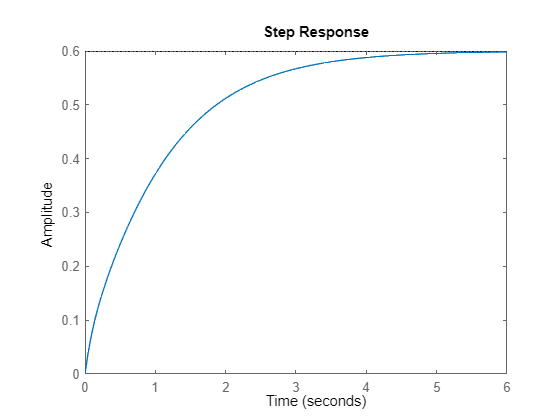

G2=tf(6/13*[1 13/5],[1 3 2]);
G1=zpk([-3 -4],[-1 -2],1/10);

figure(1)
clf
step(G)

$$f = \frac{\left(s+3\right)\,\left(s+4\right)}{s^{3}+13\,s^{2}+32\,s+20}$$

hold on

$$ans = \frac{2}{3\,\left(s+1\right)}-\frac{1}{4\,\left(s+2\right)}+\frac{7}{12\,\left(s+10\right)}$$

step(G1)
step(G2)

$$expre = \frac{5\,s+13}{12\,\left(s^{2}+3\,s+2\right)}$$

legend({'G','G_1','G_2'})

$$Eqnn = 5\,s+13$$

$$Eqnd = 12\,s^{2}+36\,s+24$$

**Ejemplo 2**

Supongamos que tenemos la siguiente función de transferencia

clear;clc
G=zpk([0.8 -0.4],[0.81 0.1-0.3i 0.1+0.3i],1,1)
figure(1)
clf
step(G)

Cancelando el cero y el polo de fase mínima cercanos tenemos que $G\left(z\right)\approx k\frac{z+0\ldotp 4}{\left(z^2 -0\ldotp 2z+0\ldotp 1\right)}=G_1 \left(z\right)$. Ahora, para calcular $k$ hacemos 

syms z k
f(z)=(z-0.8)*(z+0.4)/((z-0.81)*(z^2-0.2*z+0.1));
f1(z)=(z+0.4)/(z^2-0.2*z+0.1)*k;
solve(f(1)==f1(1),k)

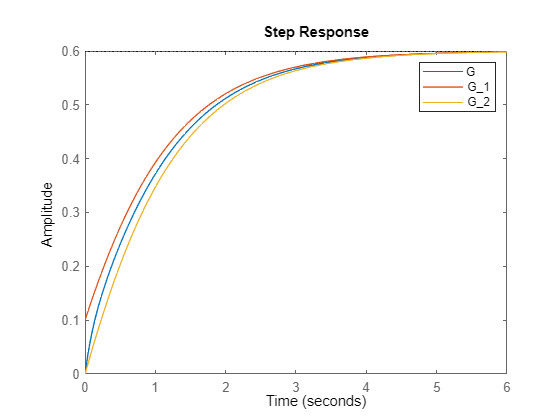

G1=tf(20/19*[1 0.4],[1 -0.2 0.1],1)
figure(2)

clf
step(G)
hold on
step(G1)
legend({'G','G_1'})

G =
 
        (z-0.8) (z+0.4)
  ---------------------------
  (z-0.81) (z^2 - 0.2z + 0.1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



#### Caso especial de reducción de orden

Los métodos de reducción de orden que hemos visto no son aplicables cuando los ceros de la función de transferencia reducida $G_1 \left(s/z\right)$ actúan como anuladores de una entrada tipo escalón dado que no es posible identificar la ganancia. Lo máximo a lo que llegaremos en estos casos es proponer $k=1$.

### Función de ponderación (Secuencia de ponderación)

Pensemos que tenemos una función de transferencia estable $G\left(z\right)$ y le aplicamos un impulso como entrada, $u\left(k\right)=\delta_k \left(k\right)$. Por el teorema de convolución, la respuesta del sistema estará dada por $y\left(k\right)=\sum_{n=0}^k g\left(n\right)\delta_k \left(k-n\right)=g\left(k\right)$, siendo $g\left(k\right)=Z^{-1} \left\lbrace G\left(z\right)\right\rbrace$. Ahora, dado que el sistema es estable, se sigue que $\lim_{k\longrightarrow \infty } g\left(k\right)=0$ y por ende, podemos aproximar esta secuencia haciendo $h_n \left(k\right)=\left\lbrace \begin{array}{ll}
g\left(k\right) & k\le n\\
0 & k>n
\end{array}\right.$. Llamaremos a $g\left(k\right)$ como la secuencia de ponderación y a $h_n \left(k\right)$ como la secuencia truncada de ponderación. Debe notarse que $g\left(k\right)$ es una caracterización completa del sistema, es decir, si conocemos la secuencia de ponderación del sistema entonces podemos calcular la respuesta del sistema a cualquier entrada haciendo convolución. De forma tal, la secuencia truncada de ponderación es una aproximación al comportamiento del sistema. Es posible realizar este mismo análisis para sistemas de tiempo contínuo con la diferencia de que no obtendremos secuencias de ponderación sino funciones de ponderación. Las secuencias de ponderación son más versátiles puesto que es posible obtener los $n$ términos de $h_n \left(k\right)$ desde $G\left(z\right)$ mediante división larga. En cualquier caso, tanto la secuencia como la función de ponderación, corresponden con la respuesta del sistema a una entrada de impulso, por tanto, se les conoce como respuesta al impulso.

#### Aproximación de la respuesta temporal mediante la secuencia de ponderación

Supongamos que tenemos la siguiente función de transferencia

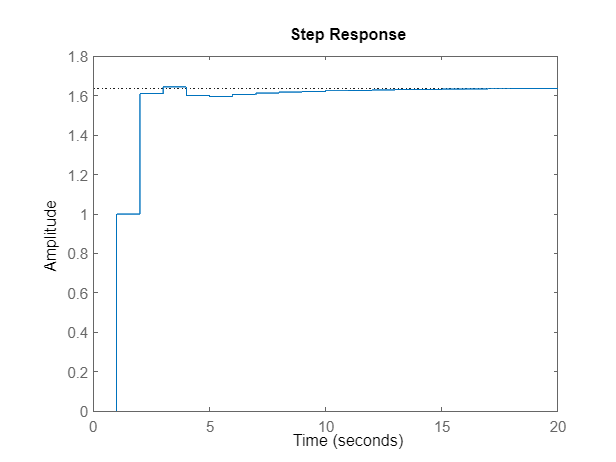

clear;clc
G=zpk([1.01 -0.4],[0.81 0.1-0.3i 0.1+0.3i],1,1)
figure(1)

clf
step(G)

Para calcular los primeros 15 términos de la secuencia de ponderación truncada empleamos la función ldiv

tf(G)
[h_n]=ldiv([0 1 -0.61 -0.404],[1 -1.01 0.262 -0.081],15)

Con esta secuencia de ponderación podemos estimar fácilmente la respuesta del sistema al escalón unitario. Esto es particularmente simple dado que, por la estructura de la convolución, la respuesta al escalón unitario es la suma acumulada de la secuencia de ponderación

y_step=cumsum(h_n);

Ahora bien, dado que la secuencia de ponderación es la respuesta al impulso del sistema. Podemos comparar la secuencia de ponderación truncada con la secuencia de ponderación haciendo

figure(2)

$$ans = \frac{20}{19}$$

clf
impulse(G)

G1 =
 
  1.053 z + 0.4211
  -----------------
  z^2 - 0.2 z + 0.1
 
Sample time: 1 seconds
Discrete-time transfer function.



hold on
stem(0:14,h_n)
legend({'G','h_n'})

Finalmente, comparamos la respuesta estimada al escalón unitario con la respuesta real del sistema haciendo

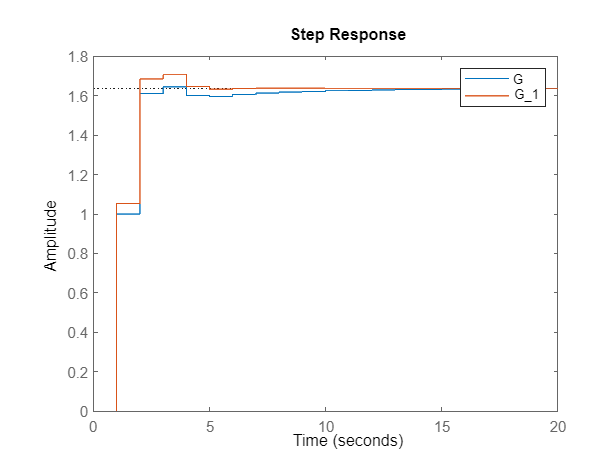

figure(3)
clf
step(G)

hold on
stem(0:14,y_step)
legend({'G','G estimada'})

### Discretización de la función de transferencia

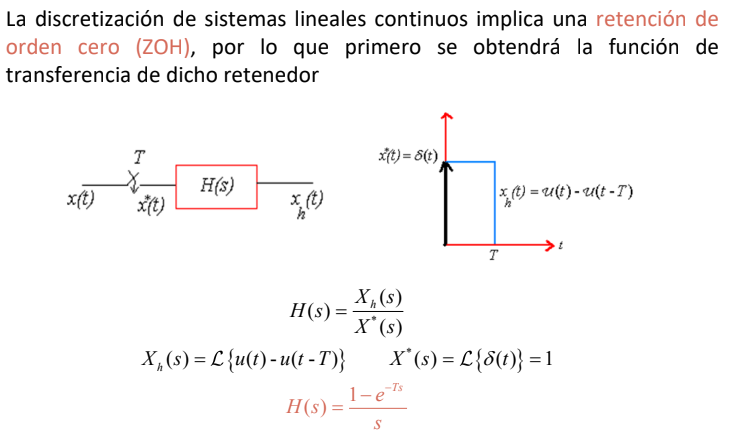

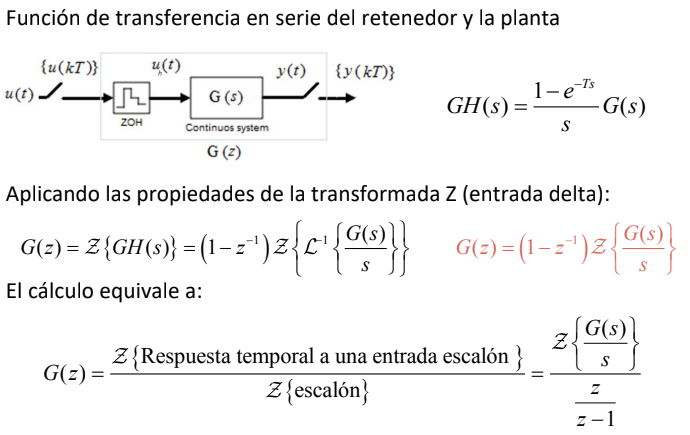

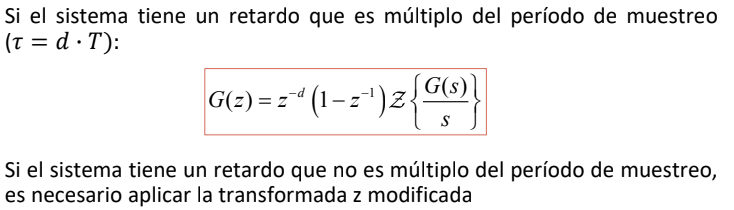

#### Transformada z modificada

La transformada z modificada (o avanzada) es una extensión de la transformada z que nos permite incorporar retardos que no son múltiplos del periodo de muestreo. La transformada z modificada tiene la forma


$$Z\left\lbrace f\left(k,d\right)\right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}+d\right)z^{-k} =F\left(z,d\right)$$


siendo


$$\begin{array}{l}
T:\textrm{el}\;\textrm{periodo}\;\textrm{de}\;\textrm{muestreo}\\
d:\textrm{el}\;\textrm{retardo}
\end{array}$$


Si consideramos que el retardo es fijo, entonces todas las propiedades de la transformada z aplican para la transformada z modificada.

#### Ejemplos de discretización

Supongamos que tenemos un modelo dado por la siguiente función de transferencia

clear;clc
G=tf([1],[6 1],'InputDelay',0.45)

G =
 
       (z-1.01) (z+0.4)
  ---------------------------
  (z-0.81) (z^2 - 0.2z + 0.1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



Ahora, si queremos discretizar este modelo con un un petriodo de muestreo tal que el retardo no sea múltiplo, por ejemplo $T=0\ldotp 2$, entonces tendremos que emplear la transformada z modificada. Por suerte, MatLab puede realizar fácilmente el proceso de discretización mediante la función [c2d](https://www.mathworks.com/help/control/ref/lti.c2d.html).

Gd=c2d(G,0.2)

## Clase 11: Introducción al espacio de estado

### Definiciones

- **Estado: **Es una caracterización completa del sistema. Consta de las ecuaciones de estado y las variables de estado. A veces, utilizaremos la palabra estado para referirnos al valor de las variables de estado en determinado instante de tiempo (también podemos llamar a esto el valor de estado).

- **Variables de estado: **Conjunto mínimo de variables $\left(\left\lbrace x_1 \left(t\right),\cdots ,x_n \left(t\right)\right\rbrace \right)$ necesarias para describir el estado. 

- **Espacio de estado: **Espacio $n-$dimensional que contiene todos los posibles valores de estado del sistema. Una representación natural para el espacio de estado se obtiene al escoger como ejes de coordenadas a las variables de estado.

- **Ecuación de estado: **Sistema de $n$ ecuaciones diferenciales de primer orden que involucran a las $n$ variables de estado. La ecuación de estado determina un campo vectorial al interior del espacio de estado, de forma tal, conocer el valor de estado para determinado momento junto con las ecuaciones de estado permite conocer el comportamiento pasado y futuro del sistema.

- **Vector de estado: **Vector formado por las variables de estado. $\mathbf{X}\left(t\right)={\left\lbrack x_1 \left(t\right),\cdots ,x_{\;n} \left(t\right)\right\rbrack }^T$.

- **Trayectoria de estado: **Colección de todos los valores asumidos por el vector de estado para un intervalo de tiempo. Puede entenderse como una curva paramétrica (trayectoria) en el espacio de estado. 

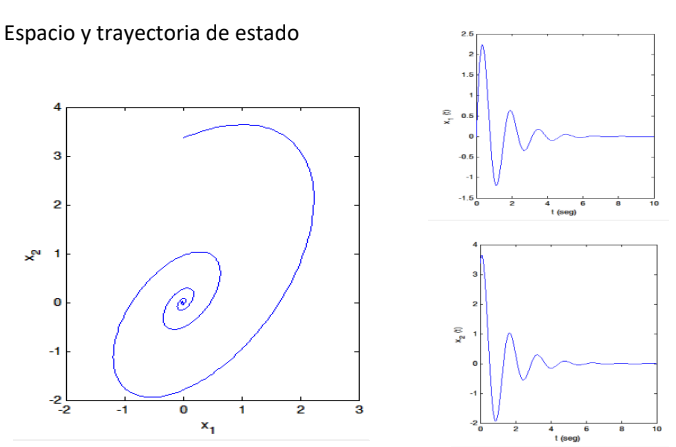

### Ecuaciones de estado

#### Ecuación en el espacio de estado continuo

Una ecuación de espacio de estado continuo tiene la forma


$$\left\lbrace \begin{array}{ll}
\left\lbrack \begin{array}{c}
\overset{\ldotp }{x_1 } \left(t\right)\\
\vdots \\
\overset{\ldotp }{x_n } \left(t\right)
\end{array}\right\rbrack = & \left\lbrack \begin{array}{c}
f_1 \left(x_1 \left(t\right),\cdots ,x_n \left(t\right),u_1 \left(t\right),\cdots ,u_m \left(t\right)\right)\\
\vdots \\
f_n \left(x_1 \left(t\right),\cdots ,x_n \left(t\right),u_1 \left(t\right),\cdots ,u_m \left(t\right)\right)
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
\vdots \\
y_p \left(t\right)
\end{array}\right\rbrack = & \left\lbrack \begin{array}{c}
g_1 \left(x_1 \left(t\right),\cdots ,x_n \left(t\right),u_1 \left(t\right),\cdots ,u_m \left(t\right)\right)\\
\vdots \\
g_p \left(x_1 \left(t\right),\cdots ,x_n \left(t\right),u_1 \left(t\right),\cdots ,u_m \left(t\right)\right)
\end{array}\right\rbrack 
\end{array}\right.$$


con $m\le n$, además, definiendo los vectores


$$\mathbf{x}\left(t\right)=\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
\vdots \\
x_n \left(t\right)
\end{array}\right\rbrack ,\mathbf{u}\left(t\right)=\left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
\vdots \\
u_m \left(t\right)
\end{array}\right\rbrack ,\mathbf{y}\left(t\right)=\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
\vdots \\
y_p \left(t\right)
\end{array}\right\rbrack$$


Podemos reescribir la ecuación de estado de la forma


$$\left\lbrace \begin{array}{ll}
\overset{\ldotp }{\mathbf{x}} \left(t\right)=\mathit{\mathbf{f}}\left(\mathbf{x}\left(t\right),\mathbf{u}\left(t\right)\right) & \\
\mathbf{y}\left(t\right)=\mathit{\mathbf{g}}\left(\mathbf{x}\left(t\right),\mathbf{u}\left(t\right)\right) & 
\end{array}\right.$$


#### Ecuación en el espacio de estado discreto

De manera similar al espacio de estado continuo, las ecuaciones en el espacio de estado discreto se pueden escribir de la forma


$$\left\lbrace \begin{array}{ll}
\mathbf{x}\left(k+1\right)=\mathit{\mathbf{f}}\left(\mathbf{x}\left(k\right),\mathbf{u}\left(k\right)\right) & \\
\mathbf{y}\left(k\right)=\mathit{\mathbf{g}}\left(\mathbf{x}\left(k\right),\mathbf{u}\left(k\right)\right) & 
\end{array}\right.$$


siendo 


$$\mathbf{x}\left(k\right)=\left\lbrack \begin{array}{c}
x_1 \left(k\right)\\
\vdots \\
x_n \left(k\right)
\end{array}\right\rbrack ,\mathbf{u}\left(k\right)=\left\lbrack \begin{array}{c}
u_1 \left(k\right)\\
\vdots \\
u_m \left(k\right)
\end{array}\right\rbrack ,\mathbf{y}\left(k\right)=\left\lbrack \begin{array}{c}
y_1 \left(k\right)\\
\vdots \\
y_p \left(k\right)
\end{array}\right\rbrack$$


Cuando las ecuaciones de estado son lineales las funciones $\mathit{\mathbf{f}}$ y $\mathit{\mathbf{g}}$ se pueden desagregar en funciones lineales para escribirlas de la forma

$\left\lbrace \begin{array}{ll}
\overset{\ldotp }{\mathbf{x}} \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right) & \\
\mathbf{y}\left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right) & 
\end{array}\right.$o  $\left\lbrace \begin{array}{ll}
\mathbf{x}\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right) & \\
\mathbf{y}\left(k\right)=\textrm{Cx}\left(k\right)+\textrm{Du}\left(k\right) & 
\end{array}\right.$, aunque normalmente, $\mathbf{D}=0$ (el sistema es propio).

### Obtención de la ecuación de estado a partir de la ecuación diferencial

Es posible llevar una ecuación de orden $n$ a una ecuación de estado mediante un cambio de variables.

#### Para sistemas continuos

Partiendo de la ecuación diferencial


$$\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_n \overset{\left(n-1\right)}{y} +\cdots +a_1 y=u & \\
y\left(0\right)=y_1 ,\cdots ,\overset{\left(n-1\right)}{y} \left(0\right)=y_n  & 
\end{array}\right.$$


Definimos $n$ variables de estado de la forma


$$\left\lbrack \begin{array}{c}
x_1 =y\\
x_2 =\overset{\ldotp }{y} \\
\vdots \\
x_n =\overset{\left(n-1\right)}{y} 
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{c}
\overset{\ldotp }{x_1 } =\overset{\ldotp }{y} =x_2 \\
\overset{\ldotp }{x_2 } =\overset{\ldotp \ldotp }{y} =x_3 \\
\vdots \\
\overset{\ldotp }{x_n } =\overset{\left(n\right)}{y} =-\left(a_n \overset{\left(n-1\right)}{y} +\cdots +a_1 y\right)+u=-\left(a_n x_n +\cdots +a_1 x_1 \right)+u
\end{array}\right\rbrack$$


Por tanto, si la ecuación original es lineal puede reescribirse como un sistema $n$ ecuaciones lineales de primer orden de la forma


$$\overset{\ldotp }{\mathbf{x}} =\underset{\mathbf{A}}{\underbrace{\left\lbrack \begin{array}{cccc}
0 & 1 & \cdots  & 0\\
0 & \ddots  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 1\\
-a_1  & {-a}_2  & \cdots  & -a_n 
\end{array}\right\rbrack } } \mathbf{x}+\underset{\mathbf{B}}{\underbrace{\left\lbrack \begin{array}{c}
0\\
\vdots \\
\vdots \\
1
\end{array}\right\rbrack } } u=\textrm{Ax}+\textrm{Bu},\;\;\mathbf{x}\left(0\right)=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_n 
\end{array}\right\rbrack$$


Resta notar que normalmente no estamos interesados en conocer el comportamiento de todas las derivadas en una ecuación diferencial. En general, encontraríamos soluciones de la forma $y=\phi \left(t\right)$, por tanto, la salida de nuestro sistema correspondería con $x_1$, es decir que 


$$\mathbf{y}=\underset{\mathbf{C}}{\underbrace{\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0
\end{array}\right\rbrack } } \mathbf{x}=\textrm{Cx}$$


**Caso especial: Presencia de derivadas en la entrada**

Si partimos de una ecuación de la forma 


$$\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_n \overset{\left(n-1\right)}{y} +\cdots +a_1 y=b_m \overset{\left(m\right)}{u} +\cdots +b_0 u & m\le n\\
 & 
\end{array}\right.$$


Entonces tendríamos problemas para representar el sistema en la forma $\textrm{Ax}+\textrm{Bu}$. Por tal razón, para obtener la ecuación de estado en este caso se añaden derivadas de la entrada en las ecuaciones de estado, empezando por la última ecuación de estado, de forma que se anulen las derivadas indeseadas. Los coeficientes de los términos que se añaden deben ser determinados cuando se calculan las derivadas de las variables de estado. En general, tendremos que añadir $\frac{m\left(m+1\right)}{2}$ términos para eliminar las derivadas de $u$. Veamos los siguientes ejemplos.

1)

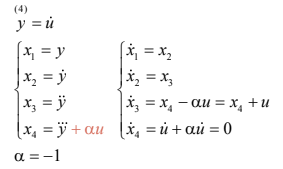    

Para esta ecuación diferencial, la ecuación de estado resultante toma la forma


$$\overset{\ldotp }{\mathbf{x}} =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \mathbf{x}+\left\lbrack \begin{array}{c}
0\\
0\\
1\\
0
\end{array}\right\rbrack u$$


2)

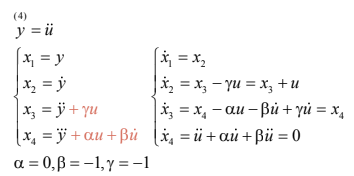

Para esta ecuación diferencial, la ecuación de estado resultante toma la forma


$$\overset{\ldotp }{\mathbf{x}} =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \mathbf{x}+\left\lbrack \begin{array}{c}
0\\
1\\
0\\
0
\end{array}\right\rbrack u$$


#### Para sistemas discretos

Se procede de manera análoga al caso de los sistemas continuos. Partiendo de la ecuación en diferencias


$$\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_n y\left(k+n-1\right)+\cdots +a_1 y\left(k\right)=u\left(k\right) & \\
y\left(0\right)=y_1 ,\cdots ,y\left(n-1\right)=y_n  & 
\end{array}\right.$$


se definen $n$ variables de estado de la forma


$$\left\lbrack \begin{array}{c}
x_1 \left(k\right)=y\left(k\right)\\
x_2 \left(k\right)=y\left(k+1\right)\\
\vdots \\
x_n \left(k\right)=y\left(k+n-1\right)
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{c}
x_1 \left(k+1\right)=y\left(k+1\right)=x_2 \left(k\right)\\
x_2 \left(k+1\right)=y\left(k+2\right)=x_3 \left(k\right)\\
\vdots \\
x_n \left(k+1\right)=y\left(k+n\right)=-\left(a_n y\left(k+n-1\right)+\cdots +a_1 y\left(k\right)\right)+u\left(k\right)=-\left(a_n x_n \left(k\right)+\cdots +a_1 x_1 \left(k\right)\right)+u\left(k\right)
\end{array}\right\rbrack$$


Por tanto, si la ecuación original es lineal puede reescribirse como un sistema $n$ ecuaciones lineales de primer orden de la forma

$\mathbf{x}\left(k+1\right)=\underset{\mathbf{A}}{\underbrace{\left\lbrack \begin{array}{cccc}
0 & 1 & \cdots  & 0\\
0 & \ddots  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 1\\
-a_1  & {-a}_2  & \cdots  & -a_n 
\end{array}\right\rbrack } } \mathbf{x}\left(k\right)+\underset{\mathbf{B}}{\underbrace{\left\lbrack \begin{array}{c}
0\\
\vdots \\
\vdots \\
1
\end{array}\right\rbrack } } u\left(k\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right),\;\;\;\mathbf{x}\left(0\right)=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_n 
\end{array}\right\rbrack$.

**Caso especial: Presencia de diferencias en la entrada**

Si partimos de una ecuación de la forma 


$$\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_n y\left(k+n-1\right)+\cdots +a_1 y\left(k\right)=b_m u\left(k+m\right)+\cdots +b_0 u\left(k\right) & m\le n\\
y\left(0\right)=y_1 ,\cdots ,y\left(n-1\right)=y_n  & 
\end{array}\right.$$


Entonces añadiremos $\frac{m\left(m+1\right)}{2}$ términos, de forma apropiada, para eliminar las diferencias de $u$. Para ver esto a través de un ejemplo, supongamos que queremos llevar a la representación en espacio de estado a la siguiente ecuación en diferencias


$$\left\lbrace \begin{array}{ll}
y\left(k+2\right)+a_2 y\left(k+1\right)+a_1 y\left(k\right)=b_2 u\left(k+2\right)+b_0 u\left(k\right) & \\
y\left(0\right)=y_1 ,\cdots ,y\left(1\right)=y_2  & 
\end{array}\right.$$


Primero, proponemos las variables de estado


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
x_1 \left(k\right)=y\left(k\right)+\gamma u\left(k\right)\\
x_2 \left(k\right)=y\left(k+1\right)+\alpha u\left(k\right)+\beta u\left(k+1\right)
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{c}
x_1 \left(k+1\right)=y\left(k+1\right)+\gamma u\left(k+1\right)=\underset{y\left(k+1\right)}{\underbrace{x_2 \left(k\right)-\alpha u\left(k\right)-\beta u\left(k+1\right)} } +\gamma u\left(k+1\right)\\
x_2 \left(k+1\right)=y\left(k+2\right)+\alpha u\left(k+1\right)+\beta u\left(k+2\right)=\underset{y\left(k+2\right)}{\underbrace{-\left(a_2 y\left(k+1\right)+a_1 y\left(k\right)\right)+b_2 u\left(k+2\right)+b_0 u\left(k\right)} } +\alpha u\left(k+1\right)+\beta u\left(k+2\right)
\end{array}\right\rbrack \\
\Longrightarrow \left\lbrack \begin{array}{c}
x_1 \left(k+1\right)=x_2 \left(k\right)-\alpha u\left(k\right)-\beta u\left(k+1\right)+\gamma u\left(k+1\right)\\
x_2 \left(k+1\right)=\underset{y\left(k+2\right)}{\underbrace{-\left(a_2 \left(\underset{y\left(k+1\right)}{\underbrace{x_2 \left(k\right)-\alpha u\left(k\right)-\beta u\left(k+1\right)} } \right)+a_1 \left(\underset{y\left(k\right)}{\underbrace{x_1 \left(k\right)-\gamma u\left(k\right)} } \right)\right)+b_2 u\left(k+2\right)+b_0 u\left(k\right)} } +\alpha u\left(k+1\right)+\beta u\left(k+2\right)
\end{array}\right\rbrack \\
\Longrightarrow \left\lbrack \begin{array}{c}
x_1 \left(k+1\right)=x_2 \left(k\right)-\alpha u\left(k\right)+\underset{0}{\underbrace{u\left(k+1\right)\left(\gamma -\beta \right)} } \\
x_2 \left(k+1\right)=-a_2 x_2 \left(k\right)-a_1 x_1 \left(k\right)+u\left(k\right)\left(a_1 \gamma +a_2 \alpha +b_0 \right)+\underset{0}{\underbrace{u\left(k+1\right)\left(a_2 \beta +\alpha \right)} } +\underset{0}{\underbrace{u\left(k+2\right)\left(b_2 +\beta \right)} } 
\end{array}\right\rbrack 
\end{array}$$


De la ecuación para $x_1 \left(k+1\right)$ resulta inmediato que $\beta =\gamma$, luego, de la ecuación para $x_2 \left(k+1\right)$ concluimos primero que $\beta =-b_2$ y con esto concluimos que $\alpha =a_2 b_2$. De forma tal


$$\left\lbrack \begin{array}{c}
x_1 \left(k+1\right)=x_2 \left(k\right)-u\left(k\right)\left(a_2 b_2 \right)\\
x_2 \left(k+1\right)=-a_2 x_2 \left(k\right)-a_1 x_1 \left(k\right)+u\left(k\right)\left(a_2^2 b_2 -a_1 b_2 +b_0 \right)
\end{array}\right\rbrack$$


y así


$$\mathbf{x}\left(k+1\right)=\underset{\mathbf{A}}{\underbrace{\left\lbrack \begin{array}{cc}
0 & 1\\
-a_1  & -a_2 
\end{array}\right\rbrack } } \mathbf{x}\left(k\right)+\underset{\mathbf{B}}{\underbrace{\left\lbrack \begin{array}{c}
-a_2 b_2 \\
a_2^2 b_2 -a_1 b_2 +b_0 
\end{array}\right\rbrack } } u\left(k\right),\;\;\;\mathbf{x}\left(0\right)=\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack$$


**Nota: **En caso de que la ecuación en diferencias esté dada hacia atrás, entonces se debe hacer el cambio de variables para que quede en diferencias hacia adelante $\left(k\longrightarrow k+n\right)$

### Solución de la ecuación lineal de estado continua

En esta sección veremos métodos de solución para el problema de la forma


$$\left\lbrace \begin{array}{ll}
\overset{\ldotp }{\mathbf{x}} =\textrm{Ax}+\textrm{Bu} & \\
\mathbf{y}=\textrm{Cx} & \mathbf{x}\left(0\right)={\mathbf{x}}_0 
\end{array}\right.$$


#### Solución mediante valores y vectores propios

Nos proponemos buscar una solución para el problema homogéneo de la forma ${\textrm{Ke}}^{\lambda t}$, de existir tal solución, tendremos entonces que 

$\lambda {\textrm{Ke}}^{\lambda t} =\mathbf{A}{\textrm{Ke}}^{\lambda t} \Longrightarrow \left(\lambda \mathbf{I}-\mathbf{A}\right){\textrm{Ke}}^{\lambda t} =0\Longrightarrow \left(\lambda \mathbf{I}-\mathbf{A}\right)\mathbf{K}=0$, es decir que $\mathbf{K}$ es un autovector de $\mathbf{A}$ asociado al valor propio $\lambda$. Ahora bien, cuando solucionamos este problema de autovalores, podemos encontrarnos con 3 casos.

- **Autovalores con multiplicidad algebráica igual a su multiplicidad geométrica. **En este caso, es posible encontrar tantos autovectores linealmente independientes como dimensión tenga $\mathbf{A}$. Luego, basta recordar que una matriz cuyas columnas están formadas por las soluciones asociadas a estos autovectores es una matriz fundamental para el sistema de ecuaciones diferenciales.

- **Autovalores complejos. **Los autovalores complejos siempre vienen en pares conjugados. Se tiene, además, que si ${\mathbf{K}}_j$ es autovector asociado al autovalor complejo $\lambda_j =\alpha +\beta \mathrm{i}$, entonces $\bar{{\mathbf{K}}_j }$ es autovector asociado con el autovalor complejo $\bar{\lambda_j } =\alpha -\beta \mathrm{i}$. Luego, recordando que la combinación lineal de soluciones de la ecuación es también solución de la ecuación, planteamos dos soluciones linealmente independientes de la forma $\left\lbrace \begin{array}{ll}
\phi_1 =\left\lbrack {\mathrm{H}}_1 \cos \beta t-{\mathrm{H}}_2 \textrm{sen}\beta t\right\rbrack e^{\alpha t}  & \\
\phi_2 =\left\lbrack {\mathrm{H}}_2 \cos \beta t+{\mathrm{H}}_1 \textrm{sen}\beta t\right\rbrack e^{\alpha t}  & {\mathrm{H}}_1 =\Re \left({\mathbf{K}}_j \right),{\mathrm{H}}_2 =\Im \left({\mathbf{K}}_j \right)
\end{array}\right.$.

- **Autovalores con multiplicidad geométrica menor a la multiplicidad algebráica. **En este caso, debemos resolver un problema de vectores propios generalizados. Cuando tenemos un autovector ${\mathbf{K}}_j$ que corresponde con cierto autovalor $\lambda_j$ para el cual queremos obtener $m$ soluciones linealmente independientes es posible demostrar que dichas soluciones tienen la forma $\left\lbrack \begin{array}{c}
\phi_1 ={\mathbf{K}}_{\textrm{j1}} e^{\lambda_j t} \\
\phi_2 ={\mathbf{K}}_{\textrm{j1}} {\textrm{te}}^{\lambda_j t} +{\mathbf{K}}_{\textrm{j2}} e^{\lambda_j t} \\
\vdots \\
\phi_m ={\mathbf{K}}_{\textrm{j1}} \frac{t^{m-1} }{\left(m-1\right)!}e^{\lambda_j t} +{\mathbf{K}}_{\textrm{j2}} \frac{t^{m-2} }{\left(m-2\right)!}e^{\lambda_j t} +\cdots +{\mathbf{K}}_{\textrm{jm}} e^{\lambda_j t} 
\end{array}\right\rbrack$, donde ${\mathbf{K}}_{\textrm{ji}} ,\mathrm{i}=1,\cdots ,m$ son una cadena de vectores propios generalizados y $\left\lbrace \phi_1 ,\cdots ,\phi_m \right\rbrace$ son las $m$ soluciones linealmente independientes. Ahora bien, la cadena de vectores propios generalizados se obtiene resolviendo $\left\lbrack \begin{array}{c}
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{j1}} =0\\
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{j2}} ={\mathbf{K}}_{\textrm{j1}} \\
\vdots \\
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{jm}} ={\mathbf{K}}_{\mathrm{j}\left(m-1\right)} 
\end{array}\right\rbrack$.

Una vez se obtiene el conjunto con las $m$ soluciones linealmente independientes $\left\lbrace \phi_1 ,\cdots ,\phi_m \right\rbrace$ se plantea la matriz fundamental $\Phi =\left\lbrack \begin{array}{ccc}
\phi_1  & \cdots  & \phi_m 
\end{array}\right\rbrack$ y con ella se plantea la matriz fundamental principal $\Psi \left(t\right)=\Phi \left(t\right)\Phi^{-1} \left(0\right)$. Luego se resuelve el problema no homogéneo por el método de variación de parámetros:


$$\mathbf{X}\left(t\right)=\Psi \left(t\right)\mathbf{x}\left(0\right)+\Psi \left(t\right)\int_0^t {\Psi \left(\tau \right)}^{-1} \left(\tau \right)\mathbf{Bu}\left(\tau \right)d\tau$$


#### Solución mediante serie de potencias (matriz exponencial o de transición del estado)

Definimos la matriz exponencial asociada a $\mathbf{A}$ como $e^{\textrm{At}} =\mathbf{I}+\textrm{At}+\frac{A^2 }{2!}t^2 +\frac{A^3 }{3!}t^3 +\cdots$. En clase se demostró que $e^{\textrm{At}}$ es matriz fundamental principal para el sistema de ecuaciones diferenciales. De forma tal, una vez se le conoce es posible utilizar la versión simplificada del método de variación de parámetros:


$$\mathbf{X}\left(t\right)=\Phi \left(t\right)\mathbf{x}\left(0\right)+\Phi \left(t\right)\int_0^t \Phi^{-1} \left(\tau \right)\textrm{Bu}\left(\tau \right)d\tau$$


A la matriz exponencial también se le conoce también como matriz de transición del estado y cuenta con las siguientes propiedades (Que se demostraron en clase). Sea $e^{\textrm{At}} =\Psi \left(t\right)$

- 
$$\Psi \left(0\right)=\mathbf{I}\ldotp$$


- 
$$\Psi^{-1} \left(t\right)=\Psi \left(-t\right)\ldotp$$


- 
$$\Psi \left(t_1 +t_2 \right)=\Psi \left(t_1 \right)\Psi \left(t_2 \right)\ldotp$$


- 
$$\Psi \left(t_2 -t_1 \right)\Psi \left(t_1 -t_0 \right)=\Psi \left(t_2 -t_0 \right)\ldotp$$


- 
$$\frac{d}{\mathrm{d}t}\Psi \left(t\right)=\mathbf{A}\Psi \left(t\right)\ldotp$$


- 
$${\left(\Psi \left(t\right)\right)}^m =\Psi \left(\textrm{mt}\right)\ldotp$$


- 
$$e^{A_1 t} e^{A_2 t} =e^{\left(A_1 +A_2 \right)t} \iff A_1 A_2 =A_2 A_1$$


Obtener la matriz exponencial no suele ser sencillo salvo algunos casos. Por ejemplo, si la matriz $\mathbf{A}$ es **diagonal**, se sigue que

$\mathbf{A}=\left\lbrack \begin{array}{ccc}
\lambda_1  &  & 0\\
 & \ddots  & \\
0 &  & \lambda_n 
\end{array}\right\rbrack \Longrightarrow e^{\textrm{At}} =\left\lbrack \begin{array}{ccc}
1 &  & 0\\
 & 1 & \\
0 &  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\lambda_1  &  & 0\\
 & \ddots  & \\
0 &  & \lambda_n 
\end{array}\right\rbrack t+\left\lbrack \begin{array}{ccc}
\frac{\lambda_1^2 }{2} &  & 0\\
 & \ddots  & \\
0 &  & \frac{\lambda_n^2 }{2}
\end{array}\right\rbrack t^2 +\left\lbrack \begin{array}{ccc}
\frac{\lambda_1^3 }{3!} &  & 0\\
 & \ddots  & \\
0 &  & \frac{\lambda_n^3 }{3!}
\end{array}\right\rbrack t^3 +\cdots =\left\lbrack \begin{array}{ccc}
1+\lambda_1 t+\frac{\lambda_1^2 }{2}t^2 +\frac{\lambda_1^3 }{3!}t^3 +\cdots  &  & 0\\
 & \ddots  & \\
0 &  & 1+\lambda_n t+\frac{\lambda_n^2 }{2}t^2 +\frac{\lambda_n^3 }{3!}t^3 +\cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
e^{\lambda_1 t}  &  & 0\\
 & \ddots  & \\
0 &  & e^{\lambda_n t} 
\end{array}\right\rbrack$.

Otro caso relativamente sencillo ocurre cuando la matriz $\mathbf{A}$ es **nilpotente**, es decir que $\exists m:{\mathbf{A}}^{m-1} \not= 0\wedge {\mathbf{A}}^m =0$. En este caso, $e^{\textrm{At}}$ puede obtenerse como una sumatoria de finitos términos (que aún pueden ser muchos). Es sabido que todos los autovalores de una matriz nilpotente son 0, es decir que la ecuación característica de una matriz nilpotente es de la forma $\lambda^n =0$, por tanto, a lo sumo tendremos que calcular $n-1$ términos de la sumatoria. Por ejemplo, todos los autovalores de la matriz

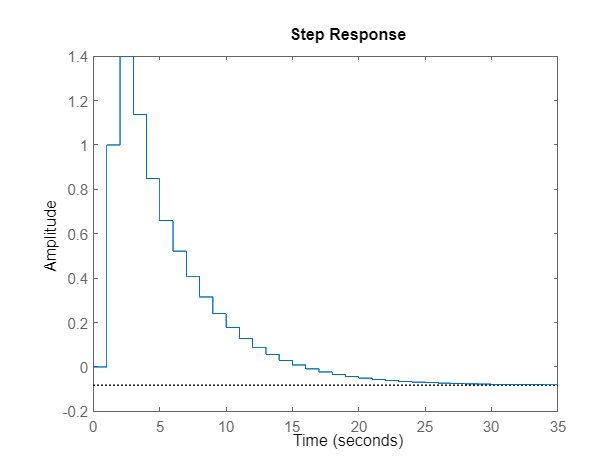

clear;clc
A=sym([0 2 1;0 0 4; 0 0 0])

son 0

eig(A)

ans =
 
        z^2 - 0.61 z - 0.404
  --------------------------------
  z^3 - 1.01 z^2 + 0.262 z - 0.081
 
Sample time: 1 seconds
Discrete-time transfer function.



Por tanto la matriz es nilpotente:

A^2

h_n =          0    1.0000    0.4000   -0.2620   -0.2884   -0.1903   -0.1378   -0.1127   -0.0931   -0.0757   -0.0612   -0.0495   -0.0401   -0.0325   -0.0263


Y así, $e^{\textrm{At}} =\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 2 & 1\\
 & 0 & 4\\
 &  & 0
\end{array}\right\rbrack t+\left\lbrack \begin{array}{ccc}
0 & 0 & 4\\
 & 0 & 0\\
 &  & 0
\end{array}\right\rbrack t^2 =\left\lbrack \begin{array}{ccc}
1 & 2t & 4t^2 +t\\
 & 1 & 4t\\
 &  & 1
\end{array}\right\rbrack$

Un caso que es similar al de la matriz nilpotente es **cuando el polinomio característico de la matriz consta de un único autovalor** ${\left(\lambda -a\right)}^n =0$. En este caso podemos explotar algunas propiedades de la matriz de transición del estado:


$$e^{\textrm{At}} =e^{\left(\mathrm{A}-\mathbf{I}\lambda +\mathbf{I}\lambda \right)t} \underset{\textrm{propiedad}\;\left(6\right)}{\Longrightarrow} e^{\textrm{At}} =e^{\left(A-\lambda \mathbf{I}\right)t} e^{\lambda t}$$


Esta última expresión es de utilidad puesto que, por el teorema de Cayley-Hamilton, la matriz $\mathbf{A}$ satisface el polinomio característico, es decir ${\left(\mathbf{A}-\lambda \mathit{\mathbf{I}}\right)}^n =0$. Por tanto, la matriz $\left(\mathbf{A}-\lambda \mathit{\mathbf{I}}\right)$ es nilpotente. Veamos el siguiente ejemplo

A=sym([2 1 1; 1 2 1; -2 -2 -1])
eig(A)

Como la matriz tiene un único autovalor, proponemos 


$$e^{\textrm{At}} =e^{\left(\mathbf{A}-\mathbf{I}\right)t} e^t$$


y comprobamos el comportamiento de la matriz $\mathbf{M}=\left(\mathbf{A}-\mathbf{I}\right)$

M=A-eye(3)
M^2

De forma tal


$$e^{\mathbf{M}} e^t =\left(\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
-2 & -2 & -2
\end{array}\right\rbrack t\right)e^t =\left\lbrack \begin{array}{ccc}
t+1 & t & t\\
t & t+1 & t\\
-2t & -2t & -2t+1
\end{array}\right\rbrack e^t =e^{\textrm{At}}$$


De una manera más general, para obtener la matriz de transición del estado tendremos que **diagonalizar** la matriz o llevarla a la **forma canónica de Jordan**. Para ello, debemos recordar que una matriz es diagonalizable siempre que todos sus autovalores tengan multiplicidad algebráica igual a su multiplicidad geométrica. En caso tal, la matriz formada por los autovectores de la matriz que queremos diagonalizar hará el proceso de diagonalización. Veamos el siguiente ejemplo:

Dada la siguiente matriz

A=sym([2 1 1; 1 2 1; 2 -2 -1])

Calculamos los valores y vectores propios haciendo

[vecs,vals]=eig(A)

Y diagonalizamos la matriz haciendo $\left\lbrack \begin{array}{ccc}
3 &  & \\
 & 1 & \\
 &  & -1
\end{array}\right\rbrack =D=P^{-1} \textrm{AP}=\left\lbrack \begin{array}{ccc}
\frac{3}{4} & \frac{1}{4} & \frac{1}{4}\\
1 & -1 & 0\\
-1 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
2 & 1 & 1\\
1 & 2 & 1\\
2 & -2 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & -\frac{1}{4}\\
1 & -1 & -\frac{1}{4}\\
0 & 1 & 1
\end{array}\right\rbrack$

inv(vecs)*A*vecs

La diagonalización de la matriz $\mathbf{A}$ es particularmente útil puesto que, como se puede demostrar fácilmente, ${\mathbf{A}}^m ={\textrm{PD}}^m {\mathbf{P}}^{-1}$ y por tal razón $e^{\textrm{At}} ={\textrm{Pe}}^{\textrm{Dt}} {\mathrm{P}}^{-1}$. Así, en el ejemplo que estamos realizando, obtenemos que 


$$e^{\textrm{At}} =\left\lbrack \begin{array}{ccc}
1 & 0 & -\frac{1}{4}\\
1 & -1 & -\frac{1}{4}\\
0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
e^{3t}  &  & \\
 & e^t  & \\
 &  & e^{-t} 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\frac{3}{4} & \frac{1}{4} & \frac{1}{4}\\
1 & -1 & 0\\
-1 & 1 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\frac{e^{-t} +3e^{3t} }{4} & \frac{e^{3t} -e^{-t} }{4} & \frac{e^{3t} -e^{-t} }{4}\\
\frac{e^{-t} +3e^{3t} }{4}-e^t  & \frac{e^{3t} -e^{-t} }{4}+e^t  & \frac{e^{3t} -e^{-t} }{4}\\
e^t -e^{-t}  & e^{-t} -e^t  & e^{-t} 
\end{array}\right\rbrack$$


Podemos comprobar este resultado en MatLab haciendo

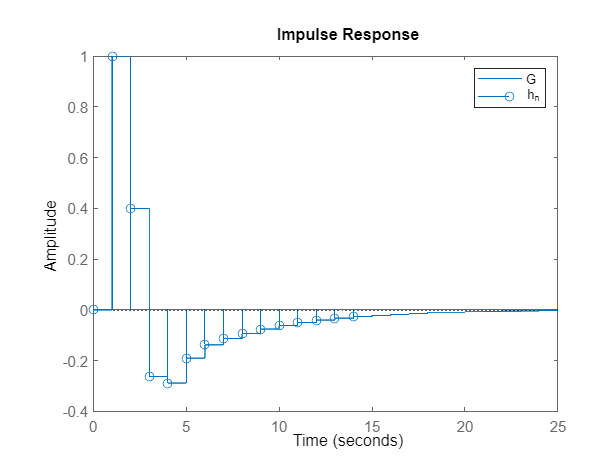

D=sym(diag([exp(3*t) exp(t) exp(-t)]))

vecs*D*inv(vecs)

O directamente calculando la matriz exponencial de $A$ con el comando *expm*.

expm(A*t)

En el caso más general, resulta que cualquier matriz puede llevarse a la **forma canónica de Jordan**. Una matriz en forma de Jordan tiene sus valores propios en la diagonal y valores de 1 sobre la diagonal para aquellos valores propios cuya multiplicidad algebráica sea menor a la geométrica. La matriz que nos permite realizar esta transformación está formada por los vectores propios generalizados, los cuales, a su vez, se obtienen al resolver una cadena de la forma 


$$\left\lbrack \begin{array}{c}
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{j1}} =0\\
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{j2}} ={\mathbf{K}}_{\textrm{j1}} \\
\vdots \\
\left(\mathbf{A}-\lambda_j \mathbf{I}\right){\mathbf{K}}_{\textrm{jm}} ={\mathbf{K}}_{\mathrm{j}\left(m-1\right)} 
\end{array}\right\rbrack$$


Tomemos un ejemplo que ya resolvimos anteriormente 

A=sym([2 1 1; 1 2 1; -2 -2 -1])

y veamos los valores y vectores propios

[vecs,vals]=eig(A)

De aquí podemos notar que la multiplicidad algebráica es mayor a la geométrica. Exploremos ahora el comportamiento de $\mathbf{M}=\left(\mathbf{A}-\mathbf{I}\right)$

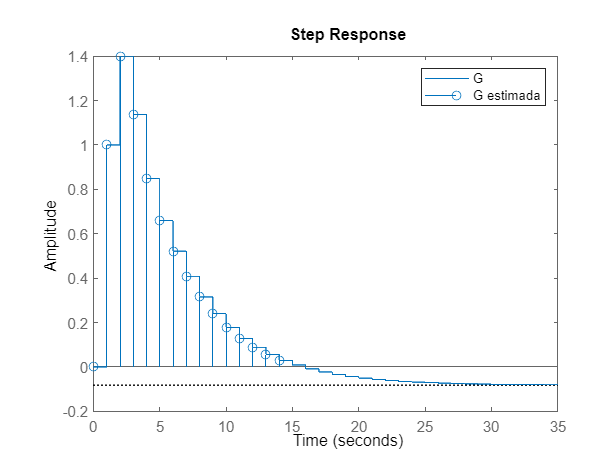

M=A-eye(3)
rank(M)
M^2

Con lo anterior notamos que el comportamiento de $\mathbf{M}$ es problemático. Debemos encontrar 1 vector linealmente independiente adicional pero el rango y el índice de nulidad nos traerán problemas. Si quisiéramos resolver el problema mediante la cadena de vectores generalizados, podríamos proponer que 

${\textrm{MK}}_2 ={\mathbf{K}}_1 \Longrightarrow \left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
-2 & -2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
1\\
0
\end{array}\right\rbrack$, pero este problema no tiene solución ya que el rango de $\mathbf{M}$ es el espacio generado por el vector $\left\lbrack \begin{array}{c}
1\\
1\\
-2
\end{array}\right\rbrack$. Ahora bien, dado que ${\mathbf{M}}^2 =0$, podemos iniciar la cadena de vectores propios generalizados partiendo desde cualquier vector. Por ejemplo

$\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
-2 & -2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
1\\
-2
\end{array}\right\rbrack$, con lo cual $\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$ y $\left\lbrack \begin{array}{c}
1\\
1\\
-2
\end{array}\right\rbrack$ son vectores propios generalizados. Para encontrar el tercer vector propio, nos dirigimos a los resultados del problema de autovalores original y elegimos $\left\lbrack \begin{array}{c}
-1\\
1\\
0
\end{array}\right\rbrack$ o $\left\lbrack \begin{array}{c}
-1\\
0\\
1
\end{array}\right\rbrack$, de forma tal, concluímos que las matrices ${\mathbf{Q}}_1 =\left\lbrack \begin{array}{ccc}
1 & 1 & -1\\
1 & 0 & 1\\
-2 & 0 & 0
\end{array}\right\rbrack$ o ${\mathbf{Q}}_2 =\left\lbrack \begin{array}{ccc}
1 & 1 & -1\\
1 & 0 & 0\\
-2 & 0 & 1
\end{array}\right\rbrack$ nos permiten llevar a la matriz $\mathbf{A}$ a la forma de Jordan. Veamos

Q1=sym([1 1 -1;1 0 1;-2 0 0]);
Q2=sym([1 1 -1;1 0 0;-2 0 1]);

G =
 
                    1
  exp(-0.45*s) * -------
                 6 s + 1
 
Continuous-time transfer function.



inv(Q1)*A*Q1
inv(Q2)*A*Q2

Gd =
 
           0.02469 z + 0.008094
  z^(-3) * --------------------
                z - 0.9672
 
Sample time: 0.2 seconds
Discrete-time transfer function.



Con eso, hemos obtenido una matriz $\mathit{\mathbf{Q}}$ tal que $\mathbf{A}={\textrm{QJQ}}^{-1}$. La utilidad de encontrar la forma de Jordan para una matriz radica en que $\mathbf{J}$ puede escribirse como la suma entre una matriz diagonal y una nilpotente $\mathbf{J}=\mathbf{D}+\mathbf{N}$, donde, adicionalmente, $\mathbf{D}$ y $\mathbf{N}$ conmutan. Así, explotando la propiedad (6) de la matriz de transición del estado, tenemos que 


$$e^{\textrm{At}} ={\textrm{Qe}}^{\textrm{Jt}} Q^{-1} ={\textrm{Qe}}^{\textrm{Dt}} e^{\textrm{Nt}} Q^{-1}$$


Y por tanto


$$\begin{array}{l}
e^{\textrm{At}} =\left\lbrack \begin{array}{ccc}
1 & 1 & -1\\
1 & 0 & 1\\
-2 & 0 & 0
\end{array}\right\rbrack \left(\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack t+\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack \frac{t^2 }{2!}+\cdots \right)\left(\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 1 & \\
 & 0 & \\
 &  & 0
\end{array}\right\rbrack t\right)\left\lbrack \begin{array}{ccc}
0 & 0 & -\frac{1}{2}\\
1 & 1 & 1\\
0 & 1 & \frac{1}{2}
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{ccc}
1 & 1 & -1\\
1 & 0 & 1\\
-2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack e^t \left\lbrack \begin{array}{ccc}
1 & t & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
0 & 0 & -\frac{1}{2}\\
1 & 1 & 1\\
0 & 1 & \frac{1}{2}
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
t+1 & t & t\\
t & t+1 & t\\
-2t & -2t & 1-2t
\end{array}\right\rbrack e^t 
\end{array}$$


Que coincide con la respuesta que se halló con anterioridad. Este resultado puede comprobarse con MatLab haciendo

Q1*[1 t 0;0 1 0;0 0 1]*inv(Q1)*exp(t)

#### Solución mediante transformada de Laplace

Es posible aplicar la transformada de Laplace para obtener la solución general del problema rápidamente. Veamos


$$\overset{\ldotp }{\mathit{\mathbf{x}}} \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\underset{L\left\lbrace \cdot \right\rbrace }{\Longrightarrow} \textrm{sX}\left(s\right)-\mathrm{x}\left(0\right)=\textrm{AX}\left(s\right)+\textrm{BU}\left(s\right)\Longrightarrow \left(\textrm{sI}-\mathrm{A}\right)\mathrm{X}\left(s\right)=\mathrm{x}\left(0\right)+\textrm{BU}\left(s\right)\Longrightarrow \mathrm{X}\left(s\right)={\left(\textrm{sI}-\mathrm{A}\right)}^{-1} \mathrm{x}\left(0\right)+{\left(\textrm{sI}-\mathrm{A}\right)}^{-1} \textrm{BU}\left(s\right)$$


Ahora, decimos que $L^{-1} \left\lbrace {\left(\textrm{sI}-\mathrm{A}\right)}^{-1} \right\rbrace =\Phi \left(t\right)$ para obtener


$$\mathrm{x}\left(t\right)=\Phi \left(t\right)\mathrm{x}\left(0\right)+\textrm{Bu}\left(t\right)\ast \Phi \left(t\right)=\Phi \left(t\right)\mathrm{x}\left(0\right)+\int_0^t \Phi \left(t-\tau \right)\mathrm{u}\left(\tau \right)\textrm{Bd}\tau$$


Pero entonces $\Phi \left(t\right)$ debe ser matriz fundamental principal (de transición del estado) y por propiedades (2) y (3) se llega a que:


$$\mathrm{x}\left(t\right)=\Phi \left(t\right)\mathrm{x}\left(0\right)+\Phi \left(t\right)\int_0^t \Phi^{-1} \left(\tau \right)\mathrm{u}\left(\tau \right)\textrm{Bd}\tau$$


#### Ejemplo 

clear;clc

$$A = \left(\begin{array}{ccc} 0 & 2 & 1\\ 0 & 0 & 4\\ 0 & 0 & 0 \end{array}\right)$$

Supongamos que queremos solucionar una ecuación de estado de la forma $\left\lbrace \begin{array}{ll}
\overset{\ldotp }{\mathbf{x}} \left(t\right)=\left\lbrack \begin{array}{ccc}
3 & 0 & 1\\
1 & 2 & -1\\
-1 & 0 & 3
\end{array}\right\rbrack \mathbf{x}\left(t\right)+\left\lbrack \begin{array}{c}
1\\
0\\
1
\end{array}\right\rbrack \textrm{sen}\left(3t\right) & \\
\mathbf{y}\left(t\right)=\left\lbrack \begin{array}{ccc}
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack \mathbf{x}\left(t\right) & \mathbf{x}\left(0\right)=\left\lbrack \begin{array}{c}
1\\
-1\\
2
\end{array}\right\rbrack 
\end{array}\right.$

Primero calcularemos la matriz de transición del estado.

syms t s c_1 c_2 c_3

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

A=sym([3 0 1;1 2 -1;-1 0 3])

Para decidir qué método elegir, calculamos los valores y vectores propios

[vecs,vals]=eig(A)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 8\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Notamos que tenemos valores propios imaginarios. Es posible calcular la matriz exponencial pero luego tendríamos que extraer la parte real, lo cual puede ser tedioso. Para evitar este proceso, decidimos seguir el procedimiento indicado para resolver la ecuación homogénea por el método de valores y vectores propios. Encontraremos entonces 3 soluciones linealmente independientes para el espacio de estado. El valor propio real nos arroja la solución

x_1=sym([0 1 0]'*exp(2*t))

Para obtener las soluciones linealmente independientes asociadas a los valores propios complejos procedemos haciendo

K=sym([1i -1 1]')

$$A = \left(\begin{array}{ccc} 2 & 1 & 1\\ 1 & 2 & 1\\ -2 & -2 & -1 \end{array}\right)$$

B_1=real(K)

$$ans = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

B_2=imag(K)
x_2=(B_1*cos(t)-B_2*sin(t))*exp(3*t)
x_3=(B_2*cos(t)+B_1*sin(t))*exp(3*t)

De tal forma, la matriz fundamental estará dada por 

phi(t)=[x_1 x_2 x_3]

$$M = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & 1\\ -2 & -2 & -2 \end{array}\right)$$

Y la matriz fundamental principal (de transición del estado) estará dada por 

psi(t)=phi(t)*inv(phi(0))

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Para solucionar el problema no homogéneo aplicamos el método de variación de parámetros

invpsi(t)=inv(psi(t))
x(t)=psi(t)*[1 -1 2]'+psi(t)*int(invpsi(t)*([1 0 1]'*sin(3*t)),[0 t])

Resolviendo llegamos a que

x(t)=simplify(x(t))

$$A = \left(\begin{array}{ccc} 2 & 1 & 1\\ 1 & 2 & 1\\ 2 & -2 & -1 \end{array}\right)$$

Ahora bien, también podríamos solucionar este problema mediante** transformada de Laplace**. Para ello hacemos

M=inv(s*eye(3)-A)

$$vecs = \left(\begin{array}{ccc} 1 & 0 & -\frac{1}{4}\\ 1 & -1 & -\frac{1}{4}\\ 0 & 1 & 1 \end{array}\right)$$

$$vals = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

psi(t)=ilaplace(M,t)

Nótese que esta matriz de transición del estado es la misma que la obtenida por el método de valores y vectores propios. Aplicando el resto del método llegamos a que

invpsi(t)=inv(psi(t));

$$ans = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

x(t)=simplify(psi(t)*[1 -1 2]'+psi(t)*int(invpsi(t)*([1 0 1]'*sin(3*t)),[0 t]))

Para graficar es recomendable crear una función

sol=matlabFunction(x)

$$D = \left(\begin{array}{ccc} {\mathrm{e}}^{3\,t} & 0 & 0\\ 0 & {\mathrm{e}}^{t} & 0\\ 0 & 0 & {\mathrm{e}}^{-t} \end{array}\right)$$

t=0:0.001:2;

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{e}}^{-t}}{4}+\frac{3\,{\mathrm{e}}^{3\,t}}{4} & \sigma_{1} & \sigma_{1}\\ \frac{{\mathrm{e}}^{-t}}{4}+\frac{3\,{\mathrm{e}}^{3\,t}}{4}-{\mathrm{e}}^{t} & \frac{{\mathrm{e}}^{3\,t}}{4}-\frac{{\mathrm{e}}^{-t}}{4}+{\mathrm{e}}^{t} & \sigma_{1}\\ {\mathrm{e}}^{t}-{\mathrm{e}}^{-t} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{t} & {\mathrm{e}}^{-t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{3\,t}}{4}-\frac{{\mathrm{e}}^{-t}}{4} \end{array}$$

Y=eye(3)*sol(t);%y(t)=Cx(t)
figure(1)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{e}}^{-t}}{4}+\frac{3\,{\mathrm{e}}^{3\,t}}{4} & \sigma_{1} & \sigma_{1}\\ \frac{{\mathrm{e}}^{-t}}{4}+\frac{3\,{\mathrm{e}}^{3\,t}}{4}-{\mathrm{e}}^{t} & \frac{{\mathrm{e}}^{3\,t}}{4}-\frac{{\mathrm{e}}^{-t}}{4}+{\mathrm{e}}^{t} & \sigma_{1}\\ {\mathrm{e}}^{t}-{\mathrm{e}}^{-t} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{t} & {\mathrm{e}}^{-t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{3\,t}}{4}-\frac{{\mathrm{e}}^{-t}}{4} \end{array}$$

clf
subplot(3,1,1)
plot(t,Y(1,:))
title('y_1')
subplot(3,1,2)

$$A = \left(\begin{array}{ccc} 2 & 1 & 1\\ 1 & 2 & 1\\ -2 & -2 & -1 \end{array}\right)$$

plot(t,Y(2,:))
title('y_2')

$$vecs = \left(\begin{array}{cc} -1 & -1\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

$$vals = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

subplot(3,1,3)
plot(t,Y(3,:))

$$M = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & 1\\ -2 & -2 & -2 \end{array}\right)$$

title('y_3')

ans = 1

**Comprobación de resultados**

Para comprobar los resultados empleamos las funciones [ss](https://www.mathworks.com/help/control/ref/ss.html) y [lsim](https://www.mathworks.com/help/control/ref/lti.lsim.html) de MatLab de la siguiente forma

1) Definimos las matrices del sistema en espacio de estado

A=[3 0 1;1 2 -1;-1 0 3];

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

B=[1 0 1]';
C=eye(3);
D=[0 0 0]';
x0=[1 -1 2]';

2) Creamos el modelo de espacio de estado

S=ss(A,B,C,D)

3) Creamos la entrada que aplicaremos al sistema

t=0:0.001:2;
u=sin(3*t);

$$ans = \left(\begin{array}{ccc} 1 & 1 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

4) Simulamos la respuesta del sistema a la respectiva entrada

figure(2)

$$ans = \left(\begin{array}{ccc} 1 & 1 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

clf
lsim(S,u,t,x0)
out=lsim(S,u,t,x0);

Gráfica para la primera variable de estado del modelo. Puede apreciarse que son idénticas.

figure(3)

$$ans = \left(\begin{array}{ccc} {\mathrm{e}}^{t}\,\left(t+1\right) & t\,{\mathrm{e}}^{t} & t\,{\mathrm{e}}^{t}\\ t\,{\mathrm{e}}^{t} & {\mathrm{e}}^{t}\,\left(t+1\right) & t\,{\mathrm{e}}^{t}\\ -2\,t\,{\mathrm{e}}^{t} & -2\,t\,{\mathrm{e}}^{t} & -{\mathrm{e}}^{t}\,\left(2\,t-1\right) \end{array}\right)$$

clf
plot(t,out(:,1))
hold on
plot(t,resp(1,:))

### Solución de la ecuación lineal de estado discreta

La ecuación de estado discreta se comporta de manera considerablemente distinta a la ecuación de estado continua. En general, excepto que la matriz $\mathbf{A}$ sea diagonalizable, será bastante complicado encontrar una solución mediante valores y vectores propios. Por otro lado, la naturaleza de la ecuación de estado discreta sugiere en sí misma un mecanismo iterativo para resolverse considerando que $\mathbf{A}$ es una matriz de transición del estado. Tomemos la forma general del espacio de estado discreto


$$\left\lbrace \begin{array}{ll}
\mathbf{x}\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right) & \\
\mathbf{y}\left(k\right)=\textrm{Cx}\left(k\right) & \mathbf{x}\left(0\right)={\mathbf{x}}_0 
\end{array}\right.$$


y veamos cómo podemos resolverla

#### Solución iterativa

Podemos aprovecharnos de la estructura del espacio de estado discreto para notar que 


$$\begin{array}{l}
\mathbf{x}\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)\\
\mathbf{x}\left(k+2\right)=\textrm{Ax}\left(k+1\right)+\textrm{Bu}\left(k+1\right)=\mathbf{A}\left(\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)\right)+\textrm{Bu}\left(k+1\right)={\mathbf{A}}^2 \mathit{\mathbf{x}}\left(k\right)+\textrm{ABu}\left(k\right)+\textrm{Bu}\left(k+1\right)\\
\begin{array}{l}
\vdots \\
\mathbf{x}\left(k+n\right)={\mathbf{A}}^n \mathbf{x}\left(k\right)+\sum_{j=k}^{k+n-1} {\mathbf{A}}^{k+n-1-j} \textrm{Bu}\left(j\right)
\end{array}
\end{array}$$


Ahora, haciendo $k=0$ y sustituyendo la variable $n$ resultante por la variable $k$, nuevamente, obtenemos la fórmula


$$\mathbf{x}\left(k\right)={\mathbf{A}}^k \mathbf{x}\left(0\right)+\sum_{n=0}^{k-1} {\mathbf{A}}^{k-1-n} \textrm{Bu}\left(n\right)$$


Esta expresión, sin embargo, sigue siendo difícil de resolver. Deberíamos enfocar nuestros esfuerzos entonces en obtener una expresión analítica que nos de cuenta del comportamiento de ${\mathbf{A}}^k$. Podemos calcular dicha expresión aplicando la transformada Z. Veamos.

#### Solución mediante transformada Z

Aplicamos la transformada Z sobre $\mathbf{x}\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)$ para obtener


$$\textrm{zX}\left(z\right)-\textrm{zx}\left(0\right)=\textrm{AX}\left(z\right)+\textrm{BU}\left(z\right)\Longrightarrow X\left(z\right)={\left(\textrm{zI}-A\right)}^{-1} \textrm{zx}\left(0\right)+{\left(\textrm{zI}-A\right)}^{-1} \textrm{BU}\left(z\right)={\left(\textrm{zI}-A\right)}^{-1} \textrm{zx}\left(0\right)+z^{-1} {\left(\textrm{zI}-A\right)}^{-1} \textrm{zBU}\left(z\right)$$


Ahora, de forma similar a lo que hicimos para la transformada de Laplace, definimos $\Phi \left(k\right)=Z^{-1} \left\lbrace {\left(\textrm{zI}-A\right)}^{-1} z\right\rbrace$ y así, tras aplicar la transformada Z inversa sobre la ecuación, llegamos a que


$$\mathbf{x}\left(k\right)=\Phi \left(k\right)\mathbf{x}\left(0\right)+{\left\lbrace \Phi \left(k\right)*\textrm{Bu}\left(k\right)\right\rbrace }_{k\longrightarrow k-1} =\Phi \left(k\right)\mathbf{x}\left(0\right)+{\left\lbrace \sum_{n=0}^k \Phi \left(k-n\right)\textrm{Bu}\left(n\right)\right\rbrace }_{k\longrightarrow k-1} =\Phi \left(k\right)\mathbf{x}\left(0\right)+\sum_{n=0}^{k-1} \Phi \left(k-1-n\right)\textrm{Bu}\left(n\right)$$


Claramente, aquí hemos obtenido una matriz $\Phi \left(k\right)$ que tiene ventajas con respecto al cálculo de la matriz ${\mathbf{A}}^k$, sin embargo, la convolución puede seguir siendo problemática. Ventajosamente, no es necesario realizar la convolución cuando se pueda calcular directamente a $\Psi \left(k\right)=Z^{-1} {\left\lbrace {\left(\textrm{zI}-A\right)}^{-1} \textrm{zBU}\left(z\right)\right\rbrace }_{\;k\longrightarrow k-1}$ ya que la ecuación tendría la forma


$$\mathbf{x}\left(k\right)=\Phi \left(k\right)\mathbf{x}\left(0\right)+\Psi \left(k\right)$$


#### Ejemplo

Resolvamos la siguiente ecuación de estado discreta


$$\left\lbrace \begin{array}{ll}
\mathbf{x}\left(k+1\right)=\left\lbrack \begin{array}{cc}
-0\ldotp 1 & 1\\
0 & 0\ldotp 2
\end{array}\right\rbrack \mathbf{x}\left(k\right)+\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack u\left(k\right) & u\left(k\right)=u_s \left(k\right)\\
\mathbf{y}\left(k\right)=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \mathbf{x}\left(k\right) & \mathbf{x}\left(0\right)=\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack 
\end{array}\right.$$


clear;clc
syms z k

Primero definimos las matrices involucradas, las condiciones iniciales y la entrada

A=[-0.1 1;0 0.2];
B=[1 1]';

$$A = \left(\begin{array}{ccc} 3 & 0 & 1\\ 1 & 2 & -1\\ -1 & 0 & 3 \end{array}\right)$$

C=eye(2);
D=[0 0]';

$$vecs = \left(\begin{array}{ccc} 0 & \mathrm{i} & -\mathrm{i}\\ 1 & -1 & -1\\ 0 & 1 & 1 \end{array}\right)$$

$$vals = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 3-\mathrm{i} & 0\\ 0 & 0 & 3+\mathrm{i} \end{array}\right)$$

u=1;
x0=[1 -1]';

$$x\_1 = \left(\begin{array}{c} 0\\ {\mathrm{e}}^{2\,t}\\ 0 \end{array}\right)$$

Luego definiremos las matrices a las que debemos calcular la transformada Z inversa

M=inv(z*eye(2)-A)*z

$$K = \left(\begin{array}{c} -\mathrm{i}\\ -1\\ 1 \end{array}\right)$$

N=M/z*B*ztrans(u,z)

$$B\_1 = \left(\begin{array}{c} 0\\ -1\\ 1 \end{array}\right)$$

Y procederemos a calcular la transformada Z inversa para obtener $\Phi \left(k\right)$ y $\Psi \left(k\right)$

phi(k)=iztrans(M,k)*x0

$$B\_2 = \left(\begin{array}{c} -1\\ 0\\ 0 \end{array}\right)$$

psi(k)=iztrans(N,k)

$$x\_2 = \left(\begin{array}{c} {\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ -{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ {\mathrm{e}}^{3\,t}\,\cos\left(t\right) \end{array}\right)$$

Finalmente, obtenemos $\mathbf{x}\left(k\right)=\Phi \left(k\right)\mathbf{x}\left(0\right)+\Psi \left(k\right)$

x(k)=simplify(phi(k)+psi(k))

$$x\_3 = \left(\begin{array}{c} -{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ -{\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ {\mathrm{e}}^{3\,t}\,\sin\left(t\right) \end{array}\right)$$

Para graficar es recomendable crear una función

sol=matlabFunction(x)

$$phi(t) = \left(\begin{array}{ccc} 0 & {\mathrm{e}}^{3\,t}\,\sin\left(t\right) & -{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ {\mathrm{e}}^{2\,t} & -{\mathrm{e}}^{3\,t}\,\cos\left(t\right) & -{\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ 0 & {\mathrm{e}}^{3\,t}\,\cos\left(t\right) & {\mathrm{e}}^{3\,t}\,\sin\left(t\right) \end{array}\right)$$

k=0:6;

$$psi(t) = \left(\begin{array}{ccc} {\mathrm{e}}^{3\,t}\,\cos\left(t\right) & 0 & {\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ {\mathrm{e}}^{3\,t}\,\sin\left(t\right) & {\mathrm{e}}^{2\,t} & {\mathrm{e}}^{2\,t}-{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ -{\mathrm{e}}^{3\,t}\,\sin\left(t\right) & 0 & {\mathrm{e}}^{3\,t}\,\cos\left(t\right) \end{array}\right)$$

Y=C*sol(k);%y(k)=Cx(k)
figure(1)
clf

$$invpsi(t) = \begin{array}{l} \left(\begin{array}{ccc} \frac{\cos\left(t\right)}{\sigma_{1}} & 0 & -\frac{\sin\left(t\right)}{\sigma_{1}}\\ -\frac{\sin\left(t\right)}{\sigma_{1}} & {\mathrm{e}}^{-2\,t} & \frac{{\mathrm{e}}^{t}\,{\cos\left(t\right)}^{2}-\cos\left(t\right)+{\mathrm{e}}^{t}\,{\sin\left(t\right)}^{2}}{\sigma_{1}}\\ \frac{\sin\left(t\right)}{\sigma_{1}} & 0 & \frac{\cos\left(t\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{3\,t}\,{\cos\left(t\right)}^{2}+{\mathrm{e}}^{3\,t}\,{\sin\left(t\right)}^{2} \end{array}$$

subplot(2,1,1)

$$x(t) = \begin{array}{l} \left(\begin{array}{c} \sigma_{3}+2\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)+{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\,\sigma_{6}+{\mathrm{e}}^{3\,t}\,\sin\left(t\right)\,\sigma_{4}\\ {\mathrm{e}}^{2\,t}-\sigma_{1}+\sigma_{2}+{\mathrm{e}}^{2\,t}\,\int_{0}^{t}\left(\frac{\sin\left(3\,t\right)\,\left({\mathrm{e}}^{t}\,{\cos\left(t\right)}^{2}-\cos\left(t\right)+{\mathrm{e}}^{t}\,{\sin\left(t\right)}^{2}\right)}{\sigma_{9}}-\sigma_{7}\right)\mathrm{d}t+\left({\mathrm{e}}^{2\,t}-\sigma_{3}\right)\,\sigma_{4}+\sigma_{5}\\ \sigma_{1}-\sigma_{2}+{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\,\sigma_{4}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ \sigma_{2}={\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ \sigma_{3}={\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ \sigma_{4}=\int_{0}^{t}\left(\sigma_{8}+\sigma_{7}\right)\mathrm{d}t\\ \sigma_{5}={\mathrm{e}}^{3\,t}\,\sin\left(t\right)\,\sigma_{6}\\ \sigma_{6}=\int_{0}^{t}\left(\sigma_{8}-\sigma_{7}\right)\mathrm{d}t\\ \sigma_{7}=\frac{\sin\left(3\,t\right)\,\sin\left(t\right)}{\sigma_{9}}\\ \sigma_{8}=\frac{\sin\left(3\,t\right)\,\cos\left(t\right)}{\sigma_{9}}\\ \sigma_{9}={\mathrm{e}}^{3\,t}\,{\cos\left(t\right)}^{2}+{\mathrm{e}}^{3\,t}\,{\sin\left(t\right)}^{2} \end{array}$$

stairs(k,Y(1,:))
title('y_1')

$$x(t) = \begin{array}{l} \left(\begin{array}{c} \frac{358\,{\mathrm{e}}^{3\,t}\,\cos\left(t\right)}{325}-\frac{56\,\sin\left(3\,t\right)}{325}-\frac{33\,\cos\left(3\,t\right)}{325}+\frac{719\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)}{325}\\ \frac{16\,{\mathrm{e}}^{2\,t}}{13}-\frac{6\,\cos\left(3\,t\right)}{325}+\frac{8\,\sin\left(3\,t\right)}{325}-\sigma_{2}+\sigma_{1}\\ \sigma_{2}-\frac{58\,\sin\left(3\,t\right)}{325}-\frac{69\,\cos\left(3\,t\right)}{325}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{358\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)}{325}\\ \sigma_{2}=\frac{719\,{\mathrm{e}}^{3\,t}\,\cos\left(t\right)}{325} \end{array}$$

subplot(2,1,2)
stairs(k,Y(2,:))
title('y_2')

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{s-3}{s^{2}-6\,s+10} & 0 & \sigma_{1}\\ \sigma_{1} & \frac{1}{s-2} & -\frac{s-4}{s^{3}-8\,s^{2}+22\,s-20}\\ -\sigma_{1} & 0 & \frac{s-3}{s^{2}-6\,s+10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{s^{2}-6\,s+10} \end{array}$$

**Comprobación de los resultados**

Para comprobar los resultados empleamos las funciones [ss](https://www.mathworks.com/help/control/ref/ss.html) y [lsim](https://www.mathworks.com/help/control/ref/lti.lsim.html) de MatLab de la siguiente forma:

Sd=ss(A,B,C,D,1)%el último parámetro es el tiempo de muestreo

$$psi(t) = \left(\begin{array}{ccc} {\mathrm{e}}^{3\,t}\,\cos\left(t\right) & 0 & {\mathrm{e}}^{3\,t}\,\sin\left(t\right)\\ {\mathrm{e}}^{3\,t}\,\sin\left(t\right) & {\mathrm{e}}^{2\,t} & {\mathrm{e}}^{2\,t}-{\mathrm{e}}^{3\,t}\,\cos\left(t\right)\\ -{\mathrm{e}}^{3\,t}\,\sin\left(t\right) & 0 & {\mathrm{e}}^{3\,t}\,\cos\left(t\right) \end{array}\right)$$

figure(2)
clf
lsim(Sd,ones(7,1),k,x0)

$$x(t) = \begin{array}{l} \left(\begin{array}{c} \frac{358\,{\mathrm{e}}^{3\,t}\,\cos\left(t\right)}{325}-\frac{56\,\sin\left(3\,t\right)}{325}-\frac{33\,\cos\left(3\,t\right)}{325}+\frac{719\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)}{325}\\ \frac{16\,{\mathrm{e}}^{2\,t}}{13}-\frac{6\,\cos\left(3\,t\right)}{325}+\frac{8\,\sin\left(3\,t\right)}{325}-\sigma_{2}+\sigma_{1}\\ \sigma_{2}-\frac{58\,\sin\left(3\,t\right)}{325}-\frac{69\,\cos\left(3\,t\right)}{325}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{358\,{\mathrm{e}}^{3\,t}\,\sin\left(t\right)}{325}\\ \sigma_{2}=\frac{719\,{\mathrm{e}}^{3\,t}\,\cos\left(t\right)}{325} \end{array}$$

### Transformaciones lineales y formas canónicas

De las secciones anteriores ya hemos visto la utilidad de las transformaciones lineales para encontrar soluciones a las ecuaciones de estado. Dichas transformaciones pueden emplearse para realizar un cambio de base para el espacio de estado. Recordemos que la base del espacio de estado está dada por las variables de estado, de forma tal, partiendo de $\mathbf{x}\left(t\right)$ podemos plantear una transformación conveniente sobre $\mathbf{A}$ de forma tal que la relación entrada-salida de la ecuación de estado se conserve. De manera general, pensemos que que $\mathbf{A}={\textrm{QJQ}}^{-1} \Longrightarrow Q^{-1} \textrm{AQ}=\mathbf{J}$, donde $\mathbf{J}$ es la forma de Jordan de la matriz $\mathbf{A}$. Ya hemos visto que la forma canónica de Jordan es particularmente útil a la hora de aplicar los métodos de solución que hemos visto. Ahora solo nos resta reescribir el espacio de estado para que se conserve la relación entrada-salida


$$\begin{array}{l}
\left\lbrace \begin{array}{ll}
{\mathbf{x}}^* \left(k+1\right)={\textrm{Jx}}^* \left(k\right)+{\mathbf{B}}^* u\left(k\right) & \\
\mathbf{y}\left(k\right)={\mathbf{C}}^* {\mathbf{x}}^* \left(k\right) & 
\end{array}\right.\Longrightarrow \mathbf{y}\left(k+1\right)={\mathbf{C}}^* \left({\textrm{Jx}}^* \left(k\right)+{\mathbf{B}}^* u\left(k\right)\right)=\mathbf{C}\left(\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)\right)\Longrightarrow \left({\mathbf{C}}^* {\textrm{Jx}}^* \left(k\right)=\textrm{CAx}\left(k\right)\wedge {\mathbf{C}}^* {\mathbf{B}}^* u\left(k\right)=\textrm{CBu}\left(k\right)\right)\\
\Longrightarrow {\mathbf{C}}^* =\textrm{CQ}\wedge {\mathbf{x}}^* =Q^{-1} x\left(k\right)\wedge {\mathbf{B}}^* =Q^{-1} B
\end{array}$$


Este mismo esquema puede seguirse con cualquier transformación lineal biyectiva (que tenga inversa). Las transformaciones lineales para el espacio de estado continuo son exactamente iguales a las del caso discreto.

#### Ejemplo

clear;clc

sol = function_handle with value:
    @(t)[cos(t.*3.0).*(-3.3e+1./3.25e+2)-sin(t.*3.0).*(5.6e+1./3.25e+2)+exp(t.*3.0).*cos(t).*(3.58e+2./3.25e+2)+exp(t.*3.0).*sin(t).*(7.19e+2./3.25e+2);cos(t.*3.0).*(-6.0./3.25e+2)+exp(t.*2.0).*(1.6e+1./1.3e+1)+sin(t.*3.0).*(8.0./3.25e+2)-exp(t.*3.0).*cos(t).*(7.19e+2./3.25e+2)+exp(t.*3.0).*sin(t).*(3.58e+2./3.25e+2);cos(t.*3.0).*(-6.9e+1./3.25e+2)-sin(t.*3.0).*(5.8e+1./3.25e+2)+exp(t.*3.0).*cos(t).*(7.19e+2./3.25e+2)-exp(t.*3.0).*sin(t).*(3.58e+2./3.25e+2)]


A=[2 1 1; 1 2 1; 2 -2 -1]
B=[1 0 1]';
C=eye(3);
D=[0 0 0]';
x0=[1 -1 2]';

Definimos el sistema en espacio de estado

S=ss(A,B,C,D);

Ahora, lo transformaremos a la forma de Jordan, para ello usamos la función [ss2ss](https://www.mathworks.com/help/control/ref/ss.ss2ss.html) una vez identifiquemos a la matriz $Q$. El argumento que debemos pasar a esta función para indicar la transformación a realizar es $Q^{-1}$.

[vecs,vals]=jordan(sym(A))
ivecs=inv(vecs)

Finalmente, transformamos el modelo haciendo

S2=ss2ss(S,double(ivecs))

### Función de transferencia MIMO

En los ejemplos que hemos visto hasta ahora de espacio de estado hemos lidiado con matrices $\mathbf{B}$ sencillas que corresponden con una única entrada al modelo, no obstante, podemos definir $\mathbf{B}$ como una matriz de $n\times m$ siendo $n$ el número de estados del sistema y $m\le n$ un número de entradas. En este caso, $\mathrm{u}\left(t/k\right)$ dejaría de ser un escalar y pasaría a ser un vector de entradas arbitrarias. Para el caso de múltiples salidas ya hemos presenciado la forma que toma $\mathbf{C}\in {\mathrm{M}}_{p\times n}$, siendo $p$ el número de salidas del sistema. Cuando un sistema tiene una única entrada y una única salida, se le conoce como **SISO **(single input - single output) mientras que cuando consta de múltiples entradas y salidas se le conoce como **MIMO** (multiple inputs - multiple outputs). Para el caso de sistemas MIMO es igualmente posible plantear una función de transferencia, pero en este caso, adquiere forma matricial, tal y como veremos a continuación.

Tenemos que la función de transferencia se define como la siguiente relación $G\left(s/z\right)=\frac{Y\left(s/z\right)}{U\left(s/z\right)}$, de forma tal aplicando la transformada de Laplace (Z) a la ecuación de estado con condiciones iniciales nulas vemos que 


$$\left\lbrace \begin{array}{ll}
\overset{\ldotp }{\mathbf{x}} \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right) & \\
\mathbf{y}\left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right) & \mathbf{x}\left(0\right)=0
\end{array}\right.\Longrightarrow \left\lbrace \begin{array}{ll}
\mathbf{X}\left(s\right)={\left(\textrm{sI}-A\right)}^{-1} \textrm{BU}\left(s\right) & \\
\mathbf{Y}\left(s\right)=\mathbf{C}{\left(\textrm{sI}-A\right)}^{-1} \textrm{BU}\left(s\right)+\textrm{DU}\left(s\right) & 
\end{array}\right.\Longrightarrow \left\lbrace \begin{array}{ll}
\mathbf{X}\left(s\right)={\left(\textrm{sI}-A\right)}^{-1} \textrm{BU}\left(s\right) & \\
G\left(s\right)=\frac{\mathbf{Y}\left(s\right)}{\mathbf{U}\left(s\right)}=\mathbf{C}{\left(\textrm{sI}-A\right)}^{-1} \mathbf{B}+\mathbf{D} & 
\end{array}\right.$$



$$\left\lbrace \begin{array}{ll}
\mathbf{x}\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right) & \\
\mathbf{y}\left(k\right)=\textrm{Cx}\left(k\right)+\textrm{Du}\left(k\right) & \mathbf{x}\left(0\right)=0
\end{array}\Longrightarrow \left\lbrace \begin{array}{ll}
\mathbf{X}\left(z\right)={\left(\textrm{zI}-A\right)}^{-1} \textrm{BU}\left(z\right) & \\
\mathbf{Y}\left(s\right)=\mathbf{C}{\left(\textrm{zI}-A\right)}^{-1} \textrm{BU}\left(s\right)+\textrm{DU}\left(s\right) & 
\end{array}\right.\Longrightarrow \left\lbrace \begin{array}{ll}
\mathbf{X}\left(z\right)={\left(\textrm{zI}-A\right)}^{-1} \textrm{BU}\left(z\right) & \\
G\left(z\right)=\frac{\mathbf{Y}\left(z\right)}{\mathbf{U}\left(z\right)}=\mathbf{C}{\left(\textrm{zI}-A\right)}^{-1} \mathbf{B}+\mathbf{D} & 
\end{array}\right.\right.$$


De forma tal, los polos del sistema estarán dados por los valores de $s/z$ para los cuales $G\left(s/z\right)\longrightarrow \infty$. Esto ocurre cuando la matriz $\left(\textrm{zI}-A\right)$ no es invertible, es decir, su determinante es 0. Por tanto, los polos del sistema corresponden con los valores propios de la matriz $\mathbf{A}$. Los ceros del sistema corresponden con quellos valores para los cuales $G\left(s/z\right)=0$, es decir, corresponden con el espacio nulo de $G$. Con lo que hemos visto hasta ahora, podemos conncluir que los conceptos de ecuación diferencial (en diferencias), ecuación de estado y función de transferencia están relacionados entre sí. De hecho, ya hemos visto cómo podemos obtener una de estas caracterizaciones del sistema a partir de la otra. El caso que no hemos visto es cómo podemos obtener la** ecuación de estado a partir de la función de transferencia**. Este último procedimiento se hace utilizando **gráficos de flujo de señal** y la **regla de Mason**, pero no exploraremos estas herramientas por el momento. 

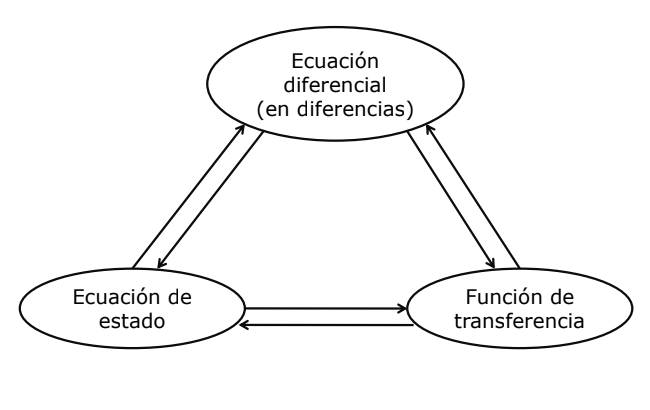

MatLab nos permite pasar de la función de transferencia a la ecuación de estado y viceversa con las funciones ss y tf, tal y como veremos a continuación

#### Ejemplos

Obtener la función de transferencia a partir de la ecuación de estado

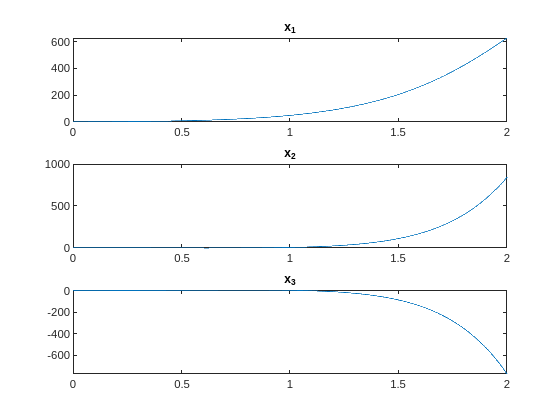

clear;clc
A=[-5 -1;3 -1];
B=[2 5; 1 0]';
C=[1 2;0 1];
D=[0]';

S=ss(A,B,C,D)
G=tf(S)


$$G\left(s\right)=\frac{1}{s^2 +6s+8}\left\lbrack \begin{array}{cc}
12s+59 & 5s+31\\
s+7 & 3
\end{array}\right\rbrack$$


Para obtener los ceros y polos de la función de transferencia hacemos

pole(G)
tzero(G)
eig(A)

Obtener la ecuación de estado a partir de la función de transferencia

G=tf([12 59],[1 6 8])
S=ss(G)

### Discretización en el espacio de estado

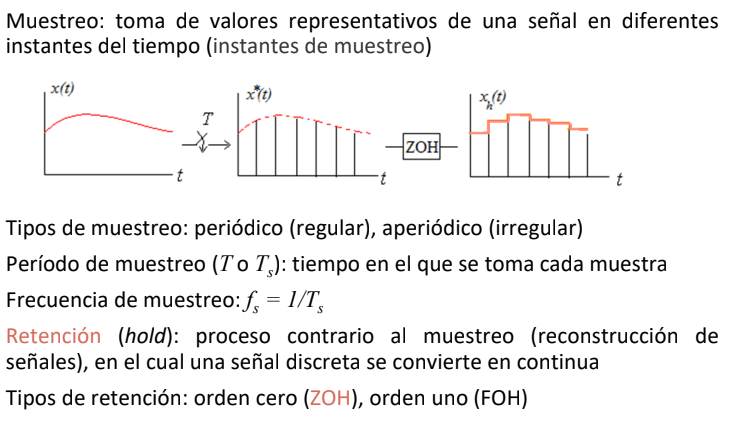

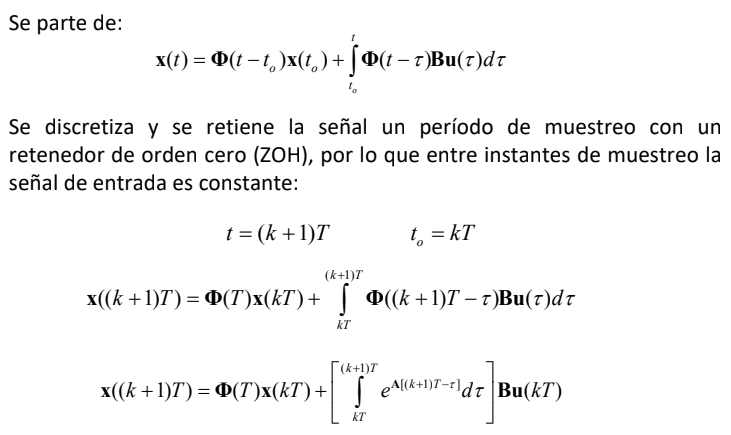

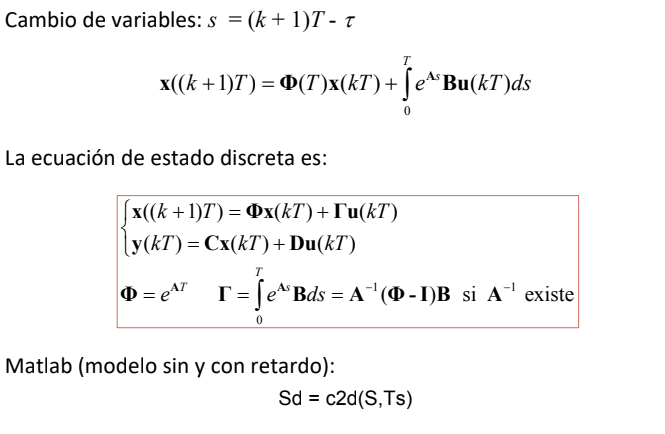

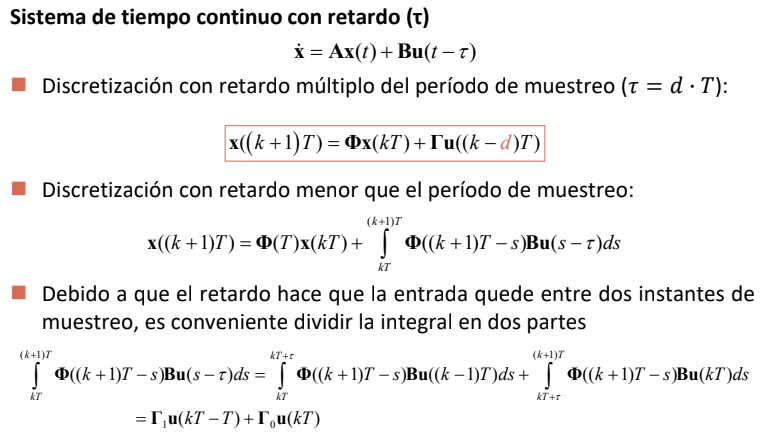

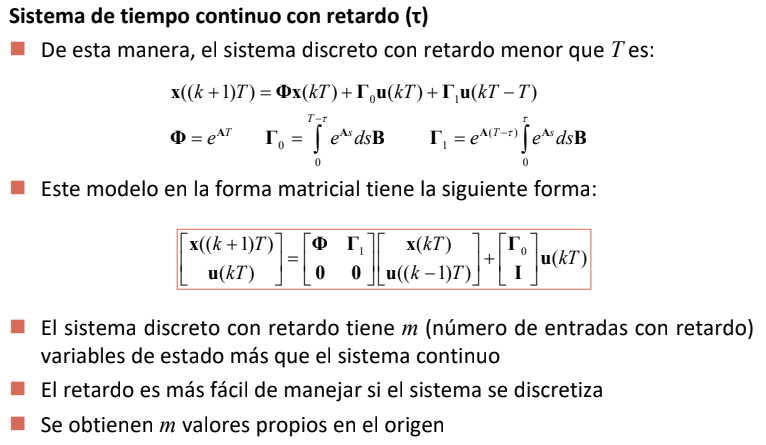

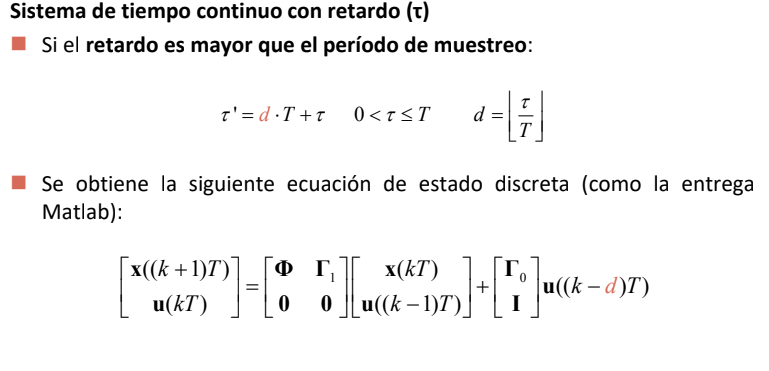

**Nota: **Para discretizar con MatLab empleamos la función [c2d](https://www.mathworks.com/help/control/ref/lti.c2d.html).

## Modelado de sistemas no lineales

### Características de los sistemas no lineales

#### Principio de superposición

#### Puntos de equlibrio

#### Bifurcación

#### Caos

#### Respuesta a entradas sinusoidales

#### Comportamiento asintótico

# Funciones adicionales para el curso

function funresult=ldiv(a,b,N)

S =
 
  A = 
       x1  x2  x3
   x1   3   0   1
   x2   1   2  -1
   x3  -1   0   3
 
  B = 
       u1
   x1   1
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



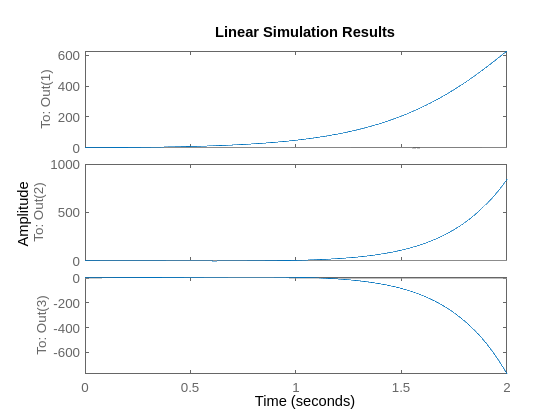

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Function (ldiv) : calculate inverse Z-transform by long division 
% Author : Tamer mohamed samy abdelazim Mellik
% Contact information : 
%Department of Electrical & Computer Engineering,
%University of Calgary,
%2500 University Drive N.W. ,

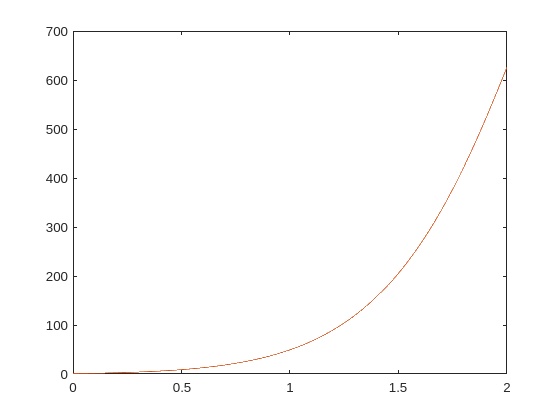

%Calgary, AB T2N 1N4 ,
%Canada .
% email :abdelasi@enel.ucalgary.ca  
% email : tabdelaz@ucalgary.ca
% Webpage : http://www.enel.ucalgary.ca/~abdelasi/
% Date    : 2-5-2002
% Version : 1.0.0
%Example

% This function like deconv but it help if the numerator less or equal degree of denominator
% if you have this function (It must arranged in terms of minus power of Z):
%              1
% G(z)= -----------------      
%             -1     -2
%      ( 5 - Z  - 3 Z  )
% and you want to calculate long division or inverse Z transform :
% The numerator  is a=[1] and  the denominator is b= [5 -1 -3 ]
% call the function ldiv(a,b) to get the funresult 20 items (default)
% another example :
%                -2     -3 
%       ( 5 - 3 Z  + 4 Z  )
%  G(z)-----------------      
%              -1     -2
%        (5 - Z  - 3 Z )
% a=[5 0 -3 4] , b= [5 -1 -3 ] and you want the funresult 100 terms !
% ldiv(a,b,100) 
% Note : The author doesn't have any responsibility for any harm caused by the use of this file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%a numerator
%b denominator
%default order of the filter == 20
funresult=[];
if nargin < 3
    if nargin > 1
            N=20;
    else
            disp('Usage: M = ldiv(a,b,N)')
            disp('a:numerator , b denominator and N is the order of the resultant filter')
            return
    end 
end

$$M = \left(\begin{array}{cc} \frac{10\,z}{10\,z+1} & \frac{50\,z}{\left(5\,z-1\right)\,\left(10\,z+1\right)}\\ 0 & \frac{5\,z}{5\,z-1} \end{array}\right)$$

if size(a) < 1

$$N = \left(\begin{array}{c} \frac{z\,\left(\frac{50}{\left(5\,z-1\right)\,\left(10\,z+1\right)}+\frac{10}{10\,z+1}\right)}{z-1}\\ \frac{5\,z}{\left(5\,z-1\right)\,\left(z-1\right)} \end{array}\right)$$

    disp('Error: numerator must at least have one element not empty')
    return

$$phi(k) = \left(\begin{array}{c} \frac{13\,{\left(-\frac{1}{10}\right)}^{k}}{3}-\frac{10\,{\left(\frac{1}{5}\right)}^{k}}{3}\\ -{\left(\frac{1}{5}\right)}^{k} \end{array}\right)$$

end

$$psi(k) = \left(\begin{array}{c} \frac{70\,{\left(-\frac{1}{10}\right)}^{k}}{33}-\frac{25\,{\left(\frac{1}{5}\right)}^{k}}{6}+\frac{45}{22}\\ \frac{5}{4}-\frac{5\,{\left(\frac{1}{5}\right)}^{k}}{4} \end{array}\right)$$

if size(b) < 1
    disp('Error: denominator must at least have one element not empty')

$$x(k) = \left(\begin{array}{c} \frac{71\,{\left(-\frac{1}{10}\right)}^{k}}{11}-\frac{15\,{\left(\frac{1}{5}\right)}^{k}}{2}+\frac{45}{22}\\ \frac{5}{4}-\frac{9}{4\,5^{k}} \end{array}\right)$$

    return
end

sol = function_handle with value:
    @(k)[(1.0./5.0).^k.*(-1.5e+1./2.0)+(-1.0./1.0e+1).^k.*(7.1e+1./1.1e+1)+4.5e+1./2.2e+1;5.0.^(-k).*(-9.0./4.0)+5.0./4.0]


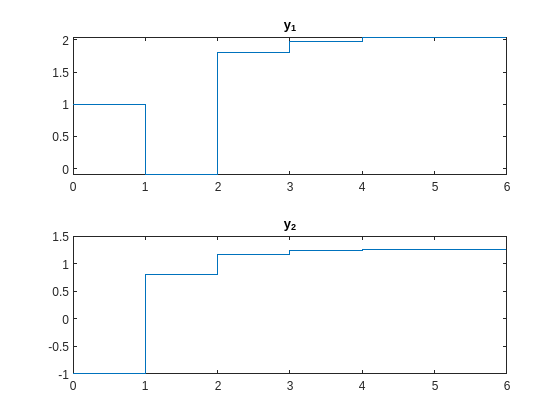

if b(1)==0
    disp('Error: The first element of denominator must have nonzero value')
    return
end
if size(b) < 2
    funresult=a./b;
    for i =length(funresult)+1:N
       funresult(i)=0;
    end
    return
end

for i = length(a)+1:N
    a(i)=0;
end
for i = 1 : N

Sd =
 
  A = 
         x1    x2
   x1  -0.1     1
   x2     0   0.2
 
  B = 
       u1
   x1   1
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 1 seconds
Discrete-time state-space model.



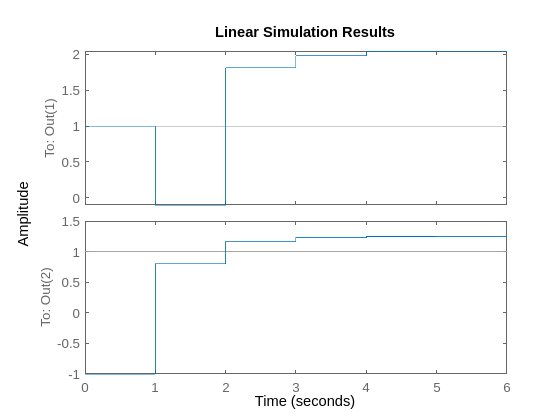

    funresult(i)=a(1)/b(1);
    if length(a)>1
            for k= 2:length(b)

                if k > length(a)
                    a(k)=0;
                end
                a(k)=a(k)-funresult(length(funresult))*b(k);
            end
        for i = 1:length(a)-1
                a(i)=a(i+1);
        end

A =      2     1     1
     1     2     1
     2    -2    -1


        a=a(1:length(a)-1);
    end
end
end

$$vecs = \left(\begin{array}{ccc} 1 & 0 & -\frac{1}{4}\\ 1 & -1 & -\frac{1}{4}\\ 0 & 1 & 1 \end{array}\right)$$

$$vals = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

$$ivecs = \left(\begin{array}{ccc} \frac{3}{4} & \frac{1}{4} & \frac{1}{4}\\ 1 & -1 & 0\\ -1 & 1 & 1 \end{array}\right)$$

S2 =
 
  A = 
       x1  x2  x3
   x1   3   0   0
   x2   0   1   0
   x3   0   0  -1
 
  B = 
       u1
   x1   1
   x2   1
   x3   0
 
  C = 
          x1     x2     x3
   y1      1      0  -0.25
   y2      1     -1  -0.25
   y3      0      1      1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



S =
 
  A = 
       x1  x2
   x1  -5  -1
   x2   3  -1
 
  B = 
       u1  u2
   x1   2   1
   x2   5   0
 
  C = 
       x1  x2
   y1   1   2
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



G =
 
  From input 1 to output...
         12 s + 59
   1:  -------------
       s^2 + 6 s + 8
 
         5 s + 31
   2:  -------------
       s^2 + 6 s + 8
 
  From input 2 to output...
           s + 7
   1:  -------------
       s^2 + 6 s + 8
 
             3
   2:  -------------
       s^2 + 6 s + 8
 
Continuous-time transfer function.



ans =     -4
    -2
    -4
    -2


ans =    -4.0000
   -2.0000


ans =     -4
    -2


G =
 
    12 s + 59
  -------------
  s^2 + 6 s + 8
 
Continuous-time transfer function.



S =
 
  A = 
       x1  x2
   x1  -6  -2
   x2   4   0
 
  B = 
       u1
   x1   4
   x2   0
 
  C = 
          x1     x2
   y1      3  3.688
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.

